# OGLO PPC

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

addpath('fieldtrip');ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


xsignal1 = [x{4}{2};x{4}{6};x{4}{10}]; % x2
xsignal2 = [x{4}{3};x{4}{7};x{4}{11}]; % x3
xsignal3 = [x{4}{4};x{4}{8};x{4}{12}]; % x4
xsignal4 = [x{5}{2};x{5}{6};x{5}{10}]; % x2
xsignal5 = [x{5}{3};x{5}{7};x{5}{7};x{5}{3}]; % x3
xsignal6 = [x{5}{4};x{5}{8};x{5}{12}]; % x4

M = min([size(xsignal1, 1), size(xsignal2, 1), size(xsignal3, 1)]);
sxs = zeros(6, M, 6000);
sxs(1, :, :) = squeeze(mean(xsignal1(1:M, 31:78, 1:6000), 2));
sxs(2, :, :) = squeeze(mean(xsignal2(1:M, 31:78, 1:6000), 2));
sxs(3, :, :) = squeeze(mean(xsignal3(1:M, 31:78, 1:6000), 2));
sxs(4, :, :) = squeeze(mean(xsignal4(1:M, 1:128, 1:6000), 2));
sxs(5, :, :) = squeeze(mean(xsignal5(1:M, 1:128, 1:6000), 2));
sxs(6, :, :) = squeeze(mean(xsignal6(1:M, 1:128, 1:6000), 2));

lk = 0.85;
ovrlp = 95;

[p1, f, t] = pspectrum(squeeze(sxs(1, 1, :)), 1000, 'spectrogram', 'FrequencyLimits', [1 100], 'Leakage', lk, 'OverlapPercent', ovrlp);

pgx = zeros([6, size(p1)]);
Tg = ceil(size(p1, 2) / 6);

for ik = 1:M

    for jk = 1:6
        [p1, f, t] = pspectrum(squeeze(sxs(jk, ik, :)), 1000, 'spectrogram', 'FrequencyLimits', [1 100], 'Leakage', lk, 'OverlapPercent', ovrlp);
        p1t = zeros([1, size(p1)]);
        p1t(1, :, :) = p1;
        pgx(jk:jk, :, :) = pgx(jk:jk, :, :) + p1t;

    end

end

for ik = 1:size(pgx, 1)

    kflag = mod(ik-1, 3) + 1;

    pbase = squeeze(mean(pgx(ik, :, ceil(Tg*(0.8 + kflag)):ceil(Tg*(0.99 + kflag))), 3));

    for jk = 1:size(pgx, 3)
    
        pgx(ik, :, jk) = squeeze(pgx(ik, :, jk)) ./ pbase;

    end

end

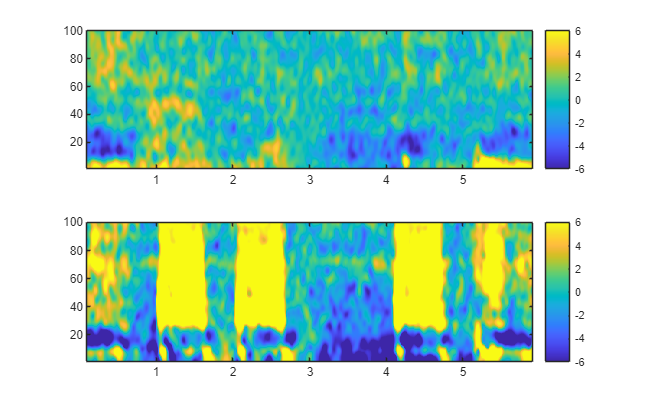

figure("Position", [0 0 2000 1500]);
clims = [-6 6];
clims2 = [-6 6];

% subplot(3, 2, 1);
% imx = (squeeze(pgx(1, :, :)) - 1)*100;
% imagesc(imx, "XData", t, "YData", f);
% clim(clims);
% title("PFC-TFR-X2");
% set(gca,'YDir','normal');colorbar;
% % xlim([1.7 3.0]);
% xline(2.000, "LineStyle", "--", "HandleVisibility", "off");
% xline(2.500, "LineStyle", "--", "HandleVisibility", "off");
% 
% subplot(3, 2, 2);
% imx = (squeeze(pgx(2, :, :)) - 1)*100;
% imagesc(imx, "XData", t, "YData", f);
% clim(clims);
% title("PFC-TFR-X3");
% set(gca,'YDir','normal');colorbar;
% % xlim([2.73 4.03]);
% xline(3.031, "LineStyle", "--", "HandleVisibility", "off");
% xline(3.531, "LineStyle", "--", "HandleVisibility", "off");

subplot(2, 1, 1);
imx = 10*log(squeeze(pgx(2, :, :)));
imagesc(imx, "XData", t, "YData", f);
clim(clims);
% xlim([0.4 6.0]);
% title("PFC-TFR-X4");
set(gca,'YDir','normal');colorbar;
% xlim([3.76 5.06]);
% xline(4.062, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.562, "LineStyle", "--", "HandleVisibility", "off");

% subplot(3, 2, 4);
% imx = (squeeze(pgx(4, :, :)) - 1)*100;
% imagesc(imx, "XData", t, "YData", f);
% clim(clims2);
% title("MTMST-TFR-X2");
% set(gca,'YDir','normal');colorbar;
% % xlim([1.7 3.0]);
% xline(2.000, "LineStyle", "--", "HandleVisibility", "off");
% xline(2.500, "LineStyle", "--", "HandleVisibility", "off");
% 
% subplot(3, 2, 5);
% imx = (squeeze(pgx(5, :, :)) - 1)*100;
% imagesc(imx, "XData", t, "YData", f);
% clim(clims2);
% title("MTMST-TFR-X3");
% set(gca,'YDir','normal');colorbar;
% % xlim([2.73 4.03]);
% xline(3.031, "LineStyle", "--", "HandleVisibility", "off");
% xline(3.531, "LineStyle", "--", "HandleVisibility", "off");

subplot(2, 1, 2);
imx = 10*log(squeeze(pgx(5, :, :)));
imagesc(imx, "XData", t, "YData", f);
clim(clims2);
% xlim([0.4 6.0]);
% title("MTMST-TFR-X4");
set(gca,'YDir','normal');colorbar;
% xlim([3.76 5.06]);
% xline(4.062, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.562, "LineStyle", "--", "HandleVisibility", "off");

fname = "PFC_MTMST_tfrs";
print(gcf,'-vector','-dsvg',fname +".svg");

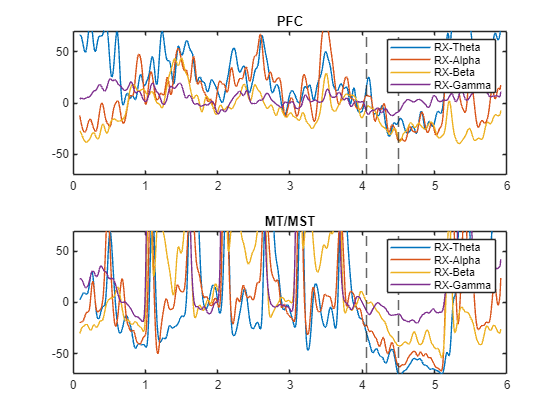

figure;
subplot(2, 1, 1);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 100*(y1t-1), "DisplayName", "RX-Theta");hold("on");
plot(t, 100*(y1a-1), "DisplayName", "RX-Alpha");
plot(t, 100*(y1b-1), "DisplayName", "RX-Beta");
plot(t, 100*(y1g-1), "DisplayName", "RX-Gamma");
xline(4.060, "LineStyle", "--", "HandleVisibility", "off");
xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
% xlim([3.750 5.000]);
ylim([-70 70]);
legend();title("PFC");

subplot(2, 1, 2);
y1t = smooth(squeeze(mean(pgx(6, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(6, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(6, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(6, 360:end, :))), 2);

plot(t, 100*(y1t-1), "DisplayName", "RX-Theta");hold("on");
plot(t, 100*(y1a-1), "DisplayName", "RX-Alpha");
plot(t, 100*(y1b-1), "DisplayName", "RX-Beta");
plot(t, 100*(y1g-1), "DisplayName", "RX-Gamma");
xline(4.060, "LineStyle", "--", "HandleVisibility", "off");
xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
% xlim([3.750 5.000]);
ylim([-70 70]);
legend();title("MT/MST");


% fname = "PFC_MT_Lplot";
% print(gcf,'-vector','-dsvg',fname +".svg");

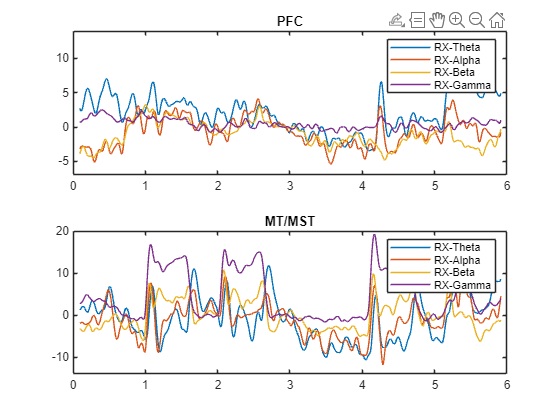

figure;
subplot(2, 1, 1);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
% xline(4.000, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("PFC");ylim([-7 14]);
% xlim([0.4 5.0]);

subplot(2, 1, 2);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 2);

plot(t, 10*log((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log((y1g)), "DisplayName", "RX-Gamma");
% xline(4.000, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MT/MST");ylim([-14 20]);
% xlim([0.4 6.0]);

fname = "PFC_MT_Lplot";
print(gcf,'-vector','-dsvg',fname +".svg");

lk = 0.85;
ovrlp = 92;

[p1, f, t] = pspectrum(squeeze(sxs(1, 1, :)), 1000, 'spectrogram', 'FrequencyLimits', [1 100], 'Leakage', lk, 'OverlapPercent', ovrlp);

pgx2 = zeros([6, size(p1)]);
Tg = ceil(size(p1, 2) / 12);

for ik = 1:M

    for jk = 1:6
        [p1, f, t] = pspectrum(squeeze(sxs(jk, ik, :)), 1000, 'spectrogram', 'FrequencyLimits', [1 100], 'Leakage', lk, 'OverlapPercent', ovrlp);
        p1t = zeros([1, size(p1)]);
        p1t(1, :, :) = p1;
        pgx2(jk:jk, :, :) = pgx2(jk:jk, :, :) + p1t;

    end

end

for ik = 1:size(pgx2, 1)


    pbase = squeeze(mean(pgx2(ik, :, Tg*3+1:Tg*4), 3));

    for jk = 1:size(pgx2, 3)
    
        pgx2(ik, :, jk) = squeeze(pgx2(ik, :, jk)) - pbase;

    end


end

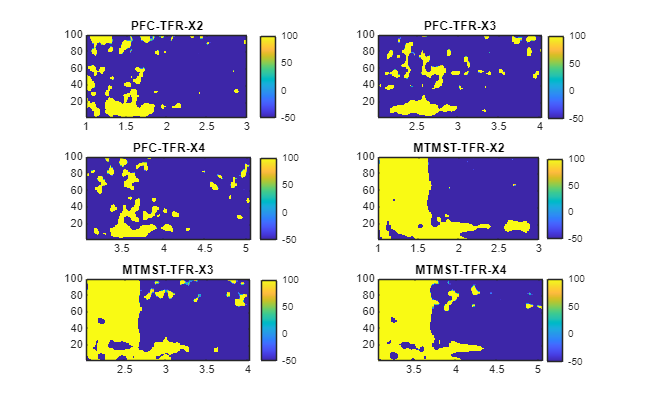

figure("Position", [0 0 2000 1500]);

subplot(3, 2, 1);
imx = (squeeze(pgx2(1, :, :)))*100;
imagesc(imx, "XData", t, "YData", f);
clim([-50 100]);
title("PFC-TFR-X2");
set(gca,'YDir','normal');colorbar;
xlim([1.0 3.0]);

subplot(3, 2, 2);
imx = (squeeze(pgx2(2, :, :)))*100;
imagesc(imx, "XData", t, "YData", f);
clim([-50 100]);
title("PFC-TFR-X3");
set(gca,'YDir','normal');colorbar;
xlim([2.03 4.03]);

subplot(3, 2, 3);
imx = (squeeze(pgx2(3, :, :)))*100;
imagesc(imx, "XData", t, "YData", f);
clim([-50 100]);
title("PFC-TFR-X4");
set(gca,'YDir','normal');colorbar;
xlim([3.06 5.06]);

subplot(3, 2, 4);
imx = (squeeze(pgx2(4, :, :)))*100;
imagesc(imx, "XData", t, "YData", f);
clim([-50 100]);
title("MTMST-TFR-X2");
set(gca,'YDir','normal');colorbar;
xlim([1.0 3.0]);

subplot(3, 2, 5);
imx = (squeeze(pgx2(5, :, :)))*100;
imagesc(imx, "XData", t, "YData", f);
clim([-50 100]);
title("MTMST-TFR-X3");
set(gca,'YDir','normal');colorbar;
xlim([2.03 4.03]);

subplot(3, 2, 6);
imx = (squeeze(pgx2(6, :, :)))*100;
imagesc(imx, "XData", t, "YData", f);
clim([-50 100]);
title("MTMST-TFR-X4");
set(gca,'YDir','normal');colorbar;
xlim([3.06 5.06]);

fname = "PFC_MTMST_tfrs2";
print(gcf,'-vector','-dsvg',fname +".svg");

figure;
subplot(2, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 2);

plot(t, log(y1t), "DisplayName", "RX-Theta");hold("on");
plot(t, log(y1a), "DisplayName", "RX-Alpha");
plot(t, log(y1b), "DisplayName", "RX-Beta");
plot(t, log(y1g), "DisplayName", "RX-Gamma");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off");
xline(2.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("PFC");

subplot(2, 1, 2);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, log(y1t), "DisplayName", "RX-Theta");hold("on");
plot(t, log(y1a), "DisplayName", "RX-Alpha");
plot(t, log(y1b), "DisplayName", "RX-Beta");
plot(t, log(y1g), "DisplayName", "RX-Gamma");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off");
xline(2.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("MT/MST");

M = min(size(xsignal1, 1), size(xsignal2, 1));
sx1 = squeeze(mean(xsignal1(1:M, :, 1:6000), 2));
sx2 = squeeze(mean(xsignal2(1:M, :, 1:6000), 2));

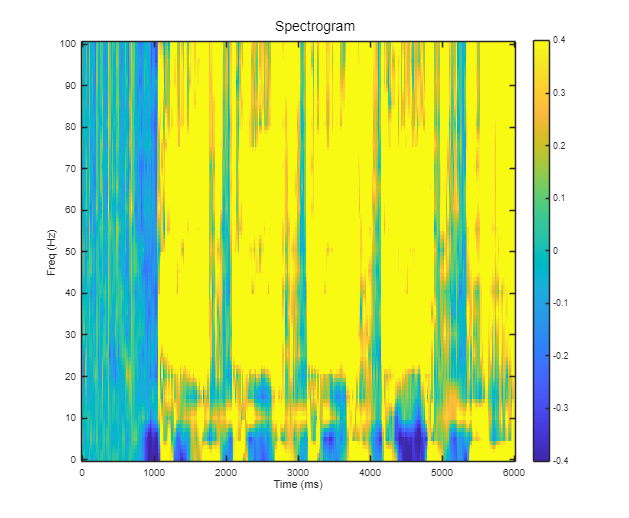

jSpectrogram(sx1, 1000, 100, 1, 200, 180, 100);

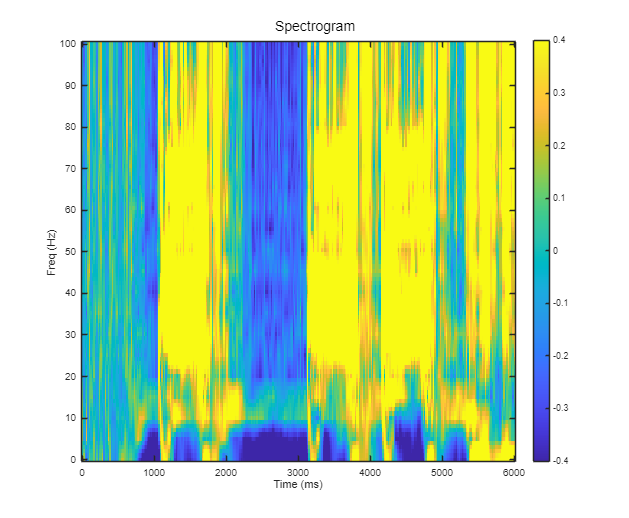

jSpectrogram(sx2, 1000, 100, 1, 200, 180, 100);

## PART 1: Select data from OGLO spiking/LFP

% xsignal = z{10}{1}{4}; % PFC-AAAB-0825-SPK
% xsignal = z{10}{4}{4}; % PFC-AAAX-0825-SPK
% xsignal = z{8}{1}{3}; % MST-AAAB-0825-SPK
% xsignal = z{8}{4}{3}; % MST-AAAX-0825-SPK

% xsignal = z{9}{1}{1}; % FEF-AAAB-0823-SPK
xsignal = z{9}{4}{1}; % FEF-AAAX-0823-SPK
% xsignal = z{8}{1}{3}; % MST-AAAB-0825-SPK
% xsignal = z{8}{4}{3}; % MST-AAAX-0825-SPK

dataspike = jSignalArrayFT(xsignal, 'N');
% xsignal = x{13}{1}; % PFC-AAAB-0825-LFP
% xsignal = x{13}{4}; % PFC-AAAX-0825-LFP
% xsignal = x{14}{1}; % MST-AAAB-0825-LFP
% xsignal = x{13}{4}; % MST-AAAX-0825-LFP

% xsignal = x{10}{1}; % FEF-AAAB-0823-LFP
% xsignal = x{10}{4}; % FEF-AAAX-0823-LFP
% xsignal = x{11}{1}; % MST-AAAB-0823-LFP
xsignal = x{11}{4}; % MST-AAAX-0823-LFP

lfp = jSignalArrayFT(xsignal(:, 1:2:128, :), 'C');

## create a spike structure from the continuous structure

spike = ft_checkdata(dataspike, 'datatype', 'spike', 'feedback', 'yes');

the input is raw data with 109 channels and 28 trials
converting raw data into spike data


lfp = ft_checkdata(lfp, 'datatype', 'raw', 'feedback', 'yes');

the input is raw data with 64 channels and 28 trials


## PART 2: COMPUTE THE SPIKE TRIGGERED SPECTRA

cfg = []; 
cfg.foi = 2:4:100; 
cfg.taper = 'hann'; 
cfg.t_ftimwin = 5./cfg.foi;     
sts = ft_spiketriggeredspectrum_convol(cfg,lfp,spike);

the input is raw data with 64 channels and 28 trials
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_convol" took 76 seconds


## PART 3: COMPUTE MEASURE OF SPIKE-FIELD ASSOCIATION

## compute the measure of phase locking strength

nNeurons = length(spike.label);
ppc_all = NaN(nNeurons, length(sts.freq));
n_spikes = NaN(nNeurons, length(sts.freq));

for iNeuron = 1:nNeurons

    if length(sts.time{iNeuron})<3, continue,end
    
    % the code to compute for a single neuron
    cfg = []; 
    cfg.spikechannel = iNeuron; 
    cfg.method = 'ppc1'; 
    stat_ppc = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
    
    % collect the data in some array for all neurons
    ppc_all(iNeuron,:) = mean(stat_ppc.ppc1, 1); % collect the ppc values across units
    n_spikes(iNeuron,:) = mean(stat_ppc.nspikes, 1); % collect the number of spikes for each neuron

end

the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 27 from 27

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 27 from 27

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 17 from 17

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 18 from 18

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 26 from 26

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 24 from 24

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 19 from 19

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 20 from 20

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 15 from 15

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 22 from 22

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 27 from 27

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 8 from 8

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 28 from 28

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds
the input is spike data with 109 channels


Please wait...
Processing trial 6 from 6

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


## PART 4: VISUALIZE INDIVIDUAL NEURONS AND COMPUTE THE PHASE HISTOGRAM

% Note: this function still expects spike data to come in continuous
% format, as one structure. 
data_all = ft_appenddata([],lfp, dataspike); 

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 0 seconds


sta_all = []; 
nNeurons = 101;

for iNeuron = 1:nNeurons

    cfg = []; 
    cfg.spikechannel = dataspike.label{iNeuron};   
    cfg.channel = lfp.label{1};
    sta = ft_spiketriggeredaverage(cfg,data_all);
    sta_all(iNeuron,:) = sta.avg; 

end   

the input is raw data with 173 channels and 28 trials


the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (7 spikes)
processing trial 2 of 28 (11 spikes)
processing trial 3 of 28 (9 spikes)
processing trial 4 of 28 (9 spikes)
processing trial 5 of 28 (8 spikes)
processing trial 6 of 28 (12 spikes)
processing trial 7 of 28 (14 spikes)
processing trial 8 of 28 (10 spikes)
processing trial 9 of 28 (15 spikes)
processing trial 10 of 28 (26 spikes)
processing trial 11 of 28 (29 spikes)
processing trial 12 of 28 (27 spikes)
processing trial 13 of 28 (32 spikes)
processing trial 14 of 28 (35 spikes)
processing trial 15 of 28 (29 spikes)
processing trial 16 of 28 (32 spikes)
processing trial 17 of 28 (22 spikes)
processing trial 18 of 28 (29 spikes)
processing trial 19 of 28 (42 spikes)
processing trial 20 of 28 (52 spikes)
processing trial 21 of 28 (64 spikes)
processing trial 22 of 2

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (4 spikes)
processing trial 2 of 28 (2 spikes)
processing trial 3 of 28 (12 spikes)
processing trial 4 of 28 (8 spikes)
processing trial 5 of 28 (11 spikes)
processing trial 6 of 28 (19 spikes)
processing trial 7 of 28 (13 spikes)
processing trial 8 of 28 (18 spikes)
processing trial 9 of 28 (21 spikes)
processing trial 10 of 28 (54 spikes)
processing trial 11 of 28 (47 spikes)
processing trial 12 of 28 (25 spikes)
processing trial 13 of 28 (43 spikes)
processing trial 14 of 28 (43 spikes)
processing trial 15 of 28 (54 spikes)
processing trial 16 of 28 (41 spikes)
processing trial 17 of 28 (24 spikes)
processing trial 18 of 28 (36 spikes)
processing trial 19 of 28 (34 spikes)
processing trial 20 of 28 (39 spikes)
processing trial 21 of 28 (52 spikes)
processing trial 22 of 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (8 spikes)
processing trial 2 of 28 (8 spikes)
processing trial 3 of 28 (13 spikes)
processing trial 4 of 28 (11 spikes)
processing trial 5 of 28 (9 spikes)
processing trial 6 of 28 (14 spikes)
processing trial 7 of 28 (17 spikes)
processing trial 8 of 28 (13 spikes)
processing trial 9 of 28 (12 spikes)
processing trial 10 of 28 (18 spikes)
processing trial 11 of 28 (18 spikes)
processing trial 12 of 28 (20 spikes)
processing trial 13 of 28 (17 spikes)
processing trial 14 of 28 (20 spikes)
processing trial 15 of 28 (26 spikes)
processing trial 16 of 28 (19 spikes)
processing trial 17 of 28 (18 spikes)
processing trial 18 of 28 (22 spikes)
processing trial 19 of 28 (22 spikes)
processing trial 20 of 28 (29 spikes)
processing trial 21 of 28 (44 spikes)
processing trial 22 of 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (7 spikes)
processing trial 2 of 28 (10 spikes)
processing trial 3 of 28 (32 spikes)
processing trial 4 of 28 (23 spikes)
processing trial 5 of 28 (32 spikes)
processing trial 6 of 28 (22 spikes)
processing trial 7 of 28 (31 spikes)
processing trial 8 of 28 (33 spikes)
processing trial 9 of 28 (30 spikes)
processing trial 10 of 28 (86 spikes)
processing trial 11 of 28 (94 spikes)
processing trial 12 of 28 (105 spikes)
processing trial 13 of 28 (89 spikes)
processing trial 14 of 28 (132 spikes)
processing trial 15 of 28 (99 spikes)
processing trial 16 of 28 (109 spikes)
processing trial 17 of 28 (122 spikes)
processing trial 18 of 28 (144 spikes)
processing trial 19 of 28 (85 spikes)
processing trial 20 of 28 (109 spikes)
processing trial 21 of 28 (102 spikes)
processing tri

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (0 spikes)
processing trial 2 of 28 (5 spikes)
processing trial 3 of 28 (7 spikes)
processing trial 4 of 28 (9 spikes)
processing trial 5 of 28 (3 spikes)
processing trial 6 of 28 (16 spikes)
processing trial 7 of 28 (3 spikes)
processing trial 8 of 28 (17 spikes)
processing trial 9 of 28 (9 spikes)
processing trial 10 of 28 (4 spikes)
processing trial 11 of 28 (7 spikes)
processing trial 12 of 28 (7 spikes)
processing trial 13 of 28 (14 spikes)
processing trial 14 of 28 (7 spikes)
processing trial 15 of 28 (8 spikes)
processing trial 16 of 28 (4 spikes)
processing trial 17 of 28 (25 spikes)
processing trial 18 of 28 (19 spikes)
processing trial 19 of 28 (35 spikes)
processing trial 20 of 28 (24 spikes)
processing trial 21 of 28 (36 spikes)
processing trial 22 of 28 (12 spi

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (2 spikes)
processing trial 2 of 28 (2 spikes)
processing trial 3 of 28 (5 spikes)
processing trial 4 of 28 (5 spikes)
processing trial 5 of 28 (8 spikes)
processing trial 6 of 28 (3 spikes)
processing trial 7 of 28 (10 spikes)
processing trial 8 of 28 (7 spikes)
processing trial 9 of 28 (3 spikes)
processing trial 10 of 28 (16 spikes)
processing trial 11 of 28 (26 spikes)
processing trial 12 of 28 (26 spikes)
processing trial 13 of 28 (33 spikes)
processing trial 14 of 28 (21 spikes)
processing trial 15 of 28 (35 spikes)
processing trial 16 of 28 (30 spikes)
processing trial 17 of 28 (69 spikes)
processing trial 18 of 28 (48 spikes)
processing trial 19 of 28 (7 spikes)
processing trial 20 of 28 (47 spikes)
processing trial 21 of 28 (44 spikes)
processing trial 22 of 28 (40

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (3 spikes)
processing trial 2 of 28 (7 spikes)
processing trial 3 of 28 (19 spikes)
processing trial 4 of 28 (10 spikes)
processing trial 5 of 28 (8 spikes)
processing trial 6 of 28 (5 spikes)
processing trial 7 of 28 (7 spikes)
processing trial 8 of 28 (16 spikes)
processing trial 9 of 28 (7 spikes)
processing trial 10 of 28 (15 spikes)
processing trial 11 of 28 (12 spikes)
processing trial 12 of 28 (21 spikes)
processing trial 13 of 28 (40 spikes)
processing trial 14 of 28 (31 spikes)
processing trial 15 of 28 (31 spikes)
processing trial 16 of 28 (32 spikes)
processing trial 17 of 28 (52 spikes)
processing trial 18 of 28 (53 spikes)
processing trial 19 of 28 (59 spikes)
processing trial 20 of 28 (61 spikes)
processing trial 21 of 28 (64 spikes)
processing trial 22 of 28 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (12 spikes)
processing trial 2 of 28 (8 spikes)
processing trial 3 of 28 (26 spikes)
processing trial 4 of 28 (21 spikes)
processing trial 5 of 28 (19 spikes)
processing trial 6 of 28 (18 spikes)
processing trial 7 of 28 (21 spikes)
processing trial 8 of 28 (23 spikes)
processing trial 9 of 28 (26 spikes)
processing trial 10 of 28 (10 spikes)
processing trial 11 of 28 (19 spikes)
processing trial 12 of 28 (34 spikes)
processing trial 13 of 28 (26 spikes)
processing trial 14 of 28 (31 spikes)
processing trial 15 of 28 (23 spikes)
processing trial 16 of 28 (30 spikes)
processing trial 17 of 28 (43 spikes)
processing trial 18 of 28 (28 spikes)
processing trial 19 of 28 (21 spikes)
processing trial 20 of 28 (35 spikes)
processing trial 21 of 28 (42 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (3 spikes)
processing trial 2 of 28 (13 spikes)
processing trial 3 of 28 (19 spikes)
processing trial 4 of 28 (22 spikes)
processing trial 5 of 28 (34 spikes)
processing trial 6 of 28 (27 spikes)
processing trial 7 of 28 (23 spikes)
processing trial 8 of 28 (29 spikes)
processing trial 9 of 28 (27 spikes)
processing trial 10 of 28 (23 spikes)
processing trial 11 of 28 (30 spikes)
processing trial 12 of 28 (52 spikes)
processing trial 13 of 28 (58 spikes)
processing trial 14 of 28 (44 spikes)
processing trial 15 of 28 (46 spikes)
processing trial 16 of 28 (42 spikes)
processing trial 17 of 28 (49 spikes)
processing trial 18 of 28 (43 spikes)
processing trial 19 of 28 (25 spikes)
processing trial 20 of 28 (42 spikes)
processing trial 21 of 28 (41 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (3 spikes)
processing trial 2 of 28 (5 spikes)
processing trial 3 of 28 (19 spikes)
processing trial 4 of 28 (11 spikes)
processing trial 5 of 28 (14 spikes)
processing trial 6 of 28 (10 spikes)
processing trial 7 of 28 (13 spikes)
processing trial 8 of 28 (9 spikes)
processing trial 9 of 28 (10 spikes)
processing trial 10 of 28 (31 spikes)
processing trial 11 of 28 (39 spikes)
processing trial 12 of 28 (38 spikes)
processing trial 13 of 28 (38 spikes)
processing trial 14 of 28 (46 spikes)
processing trial 15 of 28 (32 spikes)
processing trial 16 of 28 (57 spikes)
processing trial 17 of 28 (67 spikes)
processing trial 18 of 28 (29 spikes)
processing trial 19 of 28 (64 spikes)
processing trial 20 of 28 (51 spikes)
processing trial 21 of 28 (30 spikes)
processing trial 22 of 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (4 spikes)
processing trial 2 of 28 (3 spikes)
processing trial 3 of 28 (16 spikes)
processing trial 4 of 28 (16 spikes)
processing trial 5 of 28 (13 spikes)
processing trial 6 of 28 (15 spikes)
processing trial 7 of 28 (12 spikes)
processing trial 8 of 28 (17 spikes)
processing trial 9 of 28 (11 spikes)
processing trial 10 of 28 (16 spikes)
processing trial 11 of 28 (17 spikes)
processing trial 12 of 28 (18 spikes)
processing trial 13 of 28 (20 spikes)
processing trial 14 of 28 (15 spikes)
processing trial 15 of 28 (21 spikes)
processing trial 16 of 28 (32 spikes)
processing trial 17 of 28 (54 spikes)
processing trial 18 of 28 (42 spikes)
processing trial 19 of 28 (56 spikes)
processing trial 20 of 28 (49 spikes)
processing trial 21 of 28 (52 spikes)
processing trial 22 of

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (7 spikes)
processing trial 2 of 28 (16 spikes)
processing trial 3 of 28 (11 spikes)
processing trial 4 of 28 (24 spikes)
processing trial 5 of 28 (15 spikes)
processing trial 6 of 28 (14 spikes)
processing trial 7 of 28 (15 spikes)
processing trial 8 of 28 (16 spikes)
processing trial 9 of 28 (14 spikes)
processing trial 10 of 28 (22 spikes)
processing trial 11 of 28 (26 spikes)
processing trial 12 of 28 (32 spikes)
processing trial 13 of 28 (25 spikes)
processing trial 14 of 28 (22 spikes)
processing trial 15 of 28 (23 spikes)
processing trial 16 of 28 (22 spikes)
processing trial 17 of 28 (31 spikes)
processing trial 18 of 28 (31 spikes)
processing trial 19 of 28 (32 spikes)
processing trial 20 of 28 (29 spikes)
processing trial 21 of 28 (34 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (8 spikes)
processing trial 2 of 28 (16 spikes)
processing trial 3 of 28 (41 spikes)
processing trial 4 of 28 (20 spikes)
processing trial 5 of 28 (26 spikes)
processing trial 6 of 28 (44 spikes)
processing trial 7 of 28 (20 spikes)
processing trial 8 of 28 (20 spikes)
processing trial 9 of 28 (17 spikes)
processing trial 10 of 28 (25 spikes)
processing trial 11 of 28 (11 spikes)
processing trial 12 of 28 (7 spikes)
processing trial 13 of 28 (13 spikes)
processing trial 14 of 28 (12 spikes)
processing trial 15 of 28 (9 spikes)
processing trial 16 of 28 (12 spikes)
processing trial 17 of 28 (2 spikes)
processing trial 18 of 28 (0 spikes)
processing trial 19 of 28 (4 spikes)
processing trial 20 of 28 (5 spikes)
processing trial 21 of 28 (13 spikes)
processing trial 22 of 28 (

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (88 spikes)
processing trial 2 of 28 (101 spikes)
processing trial 3 of 28 (96 spikes)
processing trial 4 of 28 (122 spikes)
processing trial 5 of 28 (114 spikes)
processing trial 6 of 28 (112 spikes)
processing trial 7 of 28 (112 spikes)
processing trial 8 of 28 (116 spikes)
processing trial 9 of 28 (105 spikes)
processing trial 10 of 28 (112 spikes)
processing trial 11 of 28 (136 spikes)
processing trial 12 of 28 (108 spikes)
processing trial 13 of 28 (134 spikes)
processing trial 14 of 28 (113 spikes)
processing trial 15 of 28 (141 spikes)
processing trial 16 of 28 (136 spikes)
processing trial 17 of 28 (89 spikes)
processing trial 18 of 28 (120 spikes)
processing trial 19 of 28 (148 spikes)
processing trial 20 of 28 (104 spikes)
processing trial 21 of 28 (122 spikes)
pr

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (0 spikes)
processing trial 2 of 28 (0 spikes)
processing trial 3 of 28 (1 spikes)
processing trial 4 of 28 (0 spikes)
processing trial 5 of 28 (0 spikes)
processing trial 6 of 28 (0 spikes)
processing trial 7 of 28 (0 spikes)
processing trial 8 of 28 (1 spikes)
processing trial 9 of 28 (1 spikes)
processing trial 10 of 28 (4 spikes)
processing trial 11 of 28 (1 spikes)
processing trial 12 of 28 (3 spikes)
processing trial 13 of 28 (4 spikes)
processing trial 14 of 28 (1 spikes)
processing trial 15 of 28 (1 spikes)
processing trial 16 of 28 (4 spikes)
processing trial 17 of 28 (2 spikes)
processing trial 18 of 28 (0 spikes)
processing trial 19 of 28 (2 spikes)
processing trial 20 of 28 (4 spikes)
processing trial 21 of 28 (0 spikes)
processing trial 22 of 28 (0 spikes)
proc

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (12 spikes)
processing trial 2 of 28 (9 spikes)
processing trial 3 of 28 (14 spikes)
processing trial 4 of 28 (32 spikes)
processing trial 5 of 28 (25 spikes)
processing trial 6 of 28 (22 spikes)
processing trial 7 of 28 (27 spikes)
processing trial 8 of 28 (39 spikes)
processing trial 9 of 28 (27 spikes)
processing trial 10 of 28 (40 spikes)
processing trial 11 of 28 (50 spikes)
processing trial 12 of 28 (58 spikes)
processing trial 13 of 28 (59 spikes)
processing trial 14 of 28 (61 spikes)
processing trial 15 of 28 (52 spikes)
processing trial 16 of 28 (55 spikes)
processing trial 17 of 28 (57 spikes)
processing trial 18 of 28 (59 spikes)
processing trial 19 of 28 (65 spikes)
processing trial 20 of 28 (70 spikes)
processing trial 21 of 28 (60 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (25 spikes)
processing trial 2 of 28 (20 spikes)
processing trial 3 of 28 (26 spikes)
processing trial 4 of 28 (46 spikes)
processing trial 5 of 28 (54 spikes)
processing trial 6 of 28 (58 spikes)
processing trial 7 of 28 (35 spikes)
processing trial 8 of 28 (38 spikes)
processing trial 9 of 28 (32 spikes)
processing trial 10 of 28 (76 spikes)
processing trial 11 of 28 (51 spikes)
processing trial 12 of 28 (64 spikes)
processing trial 13 of 28 (62 spikes)
processing trial 14 of 28 (58 spikes)
processing trial 15 of 28 (59 spikes)
processing trial 16 of 28 (62 spikes)
processing trial 17 of 28 (84 spikes)
processing trial 18 of 28 (84 spikes)
processing trial 19 of 28 (74 spikes)
processing trial 20 of 28 (67 spikes)
processing trial 21 of 28 (73 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (105 spikes)
processing trial 2 of 28 (99 spikes)
processing trial 3 of 28 (98 spikes)
processing trial 4 of 28 (137 spikes)
processing trial 5 of 28 (132 spikes)
processing trial 6 of 28 (148 spikes)
processing trial 7 of 28 (130 spikes)
processing trial 8 of 28 (111 spikes)
processing trial 9 of 28 (139 spikes)
processing trial 10 of 28 (125 spikes)
processing trial 11 of 28 (115 spikes)
processing trial 12 of 28 (123 spikes)
processing trial 13 of 28 (130 spikes)
processing trial 14 of 28 (132 spikes)
processing trial 15 of 28 (114 spikes)
processing trial 16 of 28 (105 spikes)
processing trial 17 of 28 (44 spikes)
processing trial 18 of 28 (49 spikes)
processing trial 19 of 28 (58 spikes)
processing trial 20 of 28 (40 spikes)
processing trial 21 of 28 (45 spikes)
proces

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (107 spikes)
processing trial 2 of 28 (77 spikes)
processing trial 3 of 28 (84 spikes)
processing trial 4 of 28 (90 spikes)
processing trial 5 of 28 (118 spikes)
processing trial 6 of 28 (140 spikes)
processing trial 7 of 28 (103 spikes)
processing trial 8 of 28 (108 spikes)
processing trial 9 of 28 (104 spikes)
processing trial 10 of 28 (180 spikes)
processing trial 11 of 28 (181 spikes)
processing trial 12 of 28 (196 spikes)
processing trial 13 of 28 (240 spikes)
processing trial 14 of 28 (190 spikes)
processing trial 15 of 28 (228 spikes)
processing trial 16 of 28 (245 spikes)
processing trial 17 of 28 (161 spikes)
processing trial 18 of 28 (158 spikes)
processing trial 19 of 28 (223 spikes)
processing trial 20 of 28 (198 spikes)
processing trial 21 of 28 (241 spikes)
pr

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (71 spikes)
processing trial 2 of 28 (59 spikes)
processing trial 3 of 28 (58 spikes)
processing trial 4 of 28 (69 spikes)
processing trial 5 of 28 (64 spikes)
processing trial 6 of 28 (62 spikes)
processing trial 7 of 28 (54 spikes)
processing trial 8 of 28 (59 spikes)
processing trial 9 of 28 (46 spikes)
processing trial 10 of 28 (62 spikes)
processing trial 11 of 28 (37 spikes)
processing trial 12 of 28 (36 spikes)
processing trial 13 of 28 (43 spikes)
processing trial 14 of 28 (37 spikes)
processing trial 15 of 28 (36 spikes)
processing trial 16 of 28 (41 spikes)
processing trial 17 of 28 (37 spikes)
processing trial 18 of 28 (36 spikes)
processing trial 19 of 28 (52 spikes)
processing trial 20 of 28 (45 spikes)
processing trial 21 of 28 (43 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (27 spikes)
processing trial 2 of 28 (25 spikes)
processing trial 3 of 28 (22 spikes)
processing trial 4 of 28 (23 spikes)
processing trial 5 of 28 (39 spikes)
processing trial 6 of 28 (35 spikes)
processing trial 7 of 28 (39 spikes)
processing trial 8 of 28 (33 spikes)
processing trial 9 of 28 (19 spikes)
processing trial 10 of 28 (24 spikes)
processing trial 11 of 28 (32 spikes)
processing trial 12 of 28 (36 spikes)
processing trial 13 of 28 (28 spikes)
processing trial 14 of 28 (39 spikes)
processing trial 15 of 28 (32 spikes)
processing trial 16 of 28 (26 spikes)
processing trial 17 of 28 (38 spikes)
processing trial 18 of 28 (67 spikes)
processing trial 19 of 28 (65 spikes)
processing trial 20 of 28 (44 spikes)
processing trial 21 of 28 (54 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (20 spikes)
processing trial 2 of 28 (28 spikes)
processing trial 3 of 28 (30 spikes)
processing trial 4 of 28 (30 spikes)
processing trial 5 of 28 (29 spikes)
processing trial 6 of 28 (20 spikes)
processing trial 7 of 28 (31 spikes)
processing trial 8 of 28 (24 spikes)
processing trial 9 of 28 (20 spikes)
processing trial 10 of 28 (19 spikes)
processing trial 11 of 28 (18 spikes)
processing trial 12 of 28 (24 spikes)
processing trial 13 of 28 (26 spikes)
processing trial 14 of 28 (21 spikes)
processing trial 15 of 28 (26 spikes)
processing trial 16 of 28 (23 spikes)
processing trial 17 of 28 (31 spikes)
processing trial 18 of 28 (25 spikes)
processing trial 19 of 28 (28 spikes)
processing trial 20 of 28 (36 spikes)
processing trial 21 of 28 (34 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (64 spikes)
processing trial 2 of 28 (63 spikes)
processing trial 3 of 28 (58 spikes)
processing trial 4 of 28 (62 spikes)
processing trial 5 of 28 (74 spikes)
processing trial 6 of 28 (51 spikes)
processing trial 7 of 28 (65 spikes)
processing trial 8 of 28 (65 spikes)
processing trial 9 of 28 (70 spikes)
processing trial 10 of 28 (48 spikes)
processing trial 11 of 28 (64 spikes)
processing trial 12 of 28 (58 spikes)
processing trial 13 of 28 (72 spikes)
processing trial 14 of 28 (60 spikes)
processing trial 15 of 28 (85 spikes)
processing trial 16 of 28 (52 spikes)
processing trial 17 of 28 (62 spikes)
processing trial 18 of 28 (55 spikes)
processing trial 19 of 28 (62 spikes)
processing trial 20 of 28 (71 spikes)
processing trial 21 of 28 (71 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (9 spikes)
processing trial 2 of 28 (11 spikes)
processing trial 3 of 28 (31 spikes)
processing trial 4 of 28 (23 spikes)
processing trial 5 of 28 (29 spikes)
processing trial 6 of 28 (28 spikes)
processing trial 7 of 28 (28 spikes)
processing trial 8 of 28 (23 spikes)
processing trial 9 of 28 (27 spikes)
processing trial 10 of 28 (54 spikes)
processing trial 11 of 28 (63 spikes)
processing trial 12 of 28 (71 spikes)
processing trial 13 of 28 (42 spikes)
processing trial 14 of 28 (51 spikes)
processing trial 15 of 28 (46 spikes)
processing trial 16 of 28 (56 spikes)
processing trial 17 of 28 (39 spikes)
processing trial 18 of 28 (47 spikes)
processing trial 19 of 28 (61 spikes)
processing trial 20 of 28 (59 spikes)
processing trial 21 of 28 (57 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (126 spikes)
processing trial 2 of 28 (115 spikes)
processing trial 3 of 28 (148 spikes)
processing trial 4 of 28 (146 spikes)
processing trial 5 of 28 (166 spikes)
processing trial 6 of 28 (127 spikes)
processing trial 7 of 28 (137 spikes)
processing trial 8 of 28 (168 spikes)
processing trial 9 of 28 (124 spikes)
processing trial 10 of 28 (105 spikes)
processing trial 11 of 28 (73 spikes)
processing trial 12 of 28 (76 spikes)
processing trial 13 of 28 (65 spikes)
processing trial 14 of 28 (84 spikes)
processing trial 15 of 28 (105 spikes)
processing trial 16 of 28 (104 spikes)
processing trial 17 of 28 (81 spikes)
processing trial 18 of 28 (70 spikes)
processing trial 19 of 28 (67 spikes)
processing trial 20 of 28 (70 spikes)
processing trial 21 of 28 (114 spikes)
process

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (20 spikes)
processing trial 2 of 28 (5 spikes)
processing trial 3 of 28 (10 spikes)
processing trial 4 of 28 (6 spikes)
processing trial 5 of 28 (16 spikes)
processing trial 6 of 28 (15 spikes)
processing trial 7 of 28 (13 spikes)
processing trial 8 of 28 (14 spikes)
processing trial 9 of 28 (9 spikes)
processing trial 10 of 28 (59 spikes)
processing trial 11 of 28 (52 spikes)
processing trial 12 of 28 (46 spikes)
processing trial 13 of 28 (41 spikes)
processing trial 14 of 28 (62 spikes)
processing trial 15 of 28 (50 spikes)
processing trial 16 of 28 (52 spikes)
processing trial 17 of 28 (51 spikes)
processing trial 18 of 28 (32 spikes)
processing trial 19 of 28 (53 spikes)
processing trial 20 of 28 (81 spikes)
processing trial 21 of 28 (75 spikes)
processing trial 22 of 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (99 spikes)
processing trial 2 of 28 (111 spikes)
processing trial 3 of 28 (71 spikes)
processing trial 4 of 28 (80 spikes)
processing trial 5 of 28 (81 spikes)
processing trial 6 of 28 (74 spikes)
processing trial 7 of 28 (84 spikes)
processing trial 8 of 28 (87 spikes)
processing trial 9 of 28 (78 spikes)
processing trial 10 of 28 (2 spikes)
processing trial 11 of 28 (4 spikes)
processing trial 12 of 28 (2 spikes)
processing trial 13 of 28 (1 spikes)
processing trial 14 of 28 (5 spikes)
processing trial 15 of 28 (2 spikes)
processing trial 16 of 28 (1 spikes)
processing trial 17 of 28 (8 spikes)
processing trial 18 of 28 (9 spikes)
processing trial 19 of 28 (13 spikes)
processing trial 20 of 28 (11 spikes)
processing trial 21 of 28 (7 spikes)
processing trial 22 of 28 (12

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (7 spikes)
processing trial 2 of 28 (8 spikes)
processing trial 3 of 28 (29 spikes)
processing trial 4 of 28 (7 spikes)
processing trial 5 of 28 (4 spikes)
processing trial 6 of 28 (6 spikes)
processing trial 7 of 28 (8 spikes)
processing trial 8 of 28 (8 spikes)
processing trial 9 of 28 (4 spikes)
processing trial 10 of 28 (0 spikes)
processing trial 11 of 28 (3 spikes)
processing trial 12 of 28 (0 spikes)
processing trial 13 of 28 (0 spikes)
processing trial 14 of 28 (3 spikes)
processing trial 15 of 28 (0 spikes)
processing trial 16 of 28 (1 spikes)
processing trial 17 of 28 (0 spikes)
processing trial 18 of 28 (0 spikes)
processing trial 19 of 28 (1 spikes)
processing trial 20 of 28 (9 spikes)
processing trial 21 of 28 (2 spikes)
processing trial 22 of 28 (0 spikes)
pro

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (22 spikes)
processing trial 2 of 28 (42 spikes)
processing trial 3 of 28 (79 spikes)
processing trial 4 of 28 (19 spikes)
processing trial 5 of 28 (26 spikes)
processing trial 6 of 28 (21 spikes)
processing trial 7 of 28 (29 spikes)
processing trial 8 of 28 (25 spikes)
processing trial 9 of 28 (8 spikes)
processing trial 10 of 28 (16 spikes)
processing trial 11 of 28 (23 spikes)
processing trial 12 of 28 (17 spikes)
processing trial 13 of 28 (15 spikes)
processing trial 14 of 28 (19 spikes)
processing trial 15 of 28 (19 spikes)
processing trial 16 of 28 (25 spikes)
processing trial 17 of 28 (25 spikes)
processing trial 18 of 28 (18 spikes)
processing trial 19 of 28 (25 spikes)
processing trial 20 of 28 (21 spikes)
processing trial 21 of 28 (32 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (75 spikes)
processing trial 2 of 28 (84 spikes)
processing trial 3 of 28 (140 spikes)
processing trial 4 of 28 (46 spikes)
processing trial 5 of 28 (62 spikes)
processing trial 6 of 28 (75 spikes)
processing trial 7 of 28 (98 spikes)
processing trial 8 of 28 (48 spikes)
processing trial 9 of 28 (46 spikes)
processing trial 10 of 28 (54 spikes)
processing trial 11 of 28 (37 spikes)
processing trial 12 of 28 (39 spikes)
processing trial 13 of 28 (21 spikes)
processing trial 14 of 28 (37 spikes)
processing trial 15 of 28 (31 spikes)
processing trial 16 of 28 (34 spikes)
processing trial 17 of 28 (25 spikes)
processing trial 18 of 28 (34 spikes)
processing trial 19 of 28 (33 spikes)
processing trial 20 of 28 (28 spikes)
processing trial 21 of 28 (49 spikes)
processing trial 22

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (16 spikes)
processing trial 2 of 28 (24 spikes)
processing trial 3 of 28 (59 spikes)
processing trial 4 of 28 (19 spikes)
processing trial 5 of 28 (25 spikes)
processing trial 6 of 28 (31 spikes)
processing trial 7 of 28 (25 spikes)
processing trial 8 of 28 (32 spikes)
processing trial 9 of 28 (16 spikes)
processing trial 10 of 28 (51 spikes)
processing trial 11 of 28 (25 spikes)
processing trial 12 of 28 (35 spikes)
processing trial 13 of 28 (17 spikes)
processing trial 14 of 28 (36 spikes)
processing trial 15 of 28 (63 spikes)
processing trial 16 of 28 (30 spikes)
processing trial 17 of 28 (32 spikes)
processing trial 18 of 28 (37 spikes)
processing trial 19 of 28 (100 spikes)
processing trial 20 of 28 (42 spikes)
processing trial 21 of 28 (39 spikes)
processing trial 22

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (11 spikes)
processing trial 2 of 28 (16 spikes)
processing trial 3 of 28 (48 spikes)
processing trial 4 of 28 (21 spikes)
processing trial 5 of 28 (29 spikes)
processing trial 6 of 28 (27 spikes)
processing trial 7 of 28 (17 spikes)
processing trial 8 of 28 (22 spikes)
processing trial 9 of 28 (15 spikes)
processing trial 10 of 28 (14 spikes)
processing trial 11 of 28 (16 spikes)
processing trial 12 of 28 (17 spikes)
processing trial 13 of 28 (18 spikes)
processing trial 14 of 28 (29 spikes)
processing trial 15 of 28 (29 spikes)
processing trial 16 of 28 (21 spikes)
processing trial 17 of 28 (16 spikes)
processing trial 18 of 28 (29 spikes)
processing trial 19 of 28 (5 spikes)
processing trial 20 of 28 (28 spikes)
processing trial 21 of 28 (18 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (15 spikes)
processing trial 2 of 28 (19 spikes)
processing trial 3 of 28 (29 spikes)
processing trial 4 of 28 (22 spikes)
processing trial 5 of 28 (18 spikes)
processing trial 6 of 28 (14 spikes)
processing trial 7 of 28 (14 spikes)
processing trial 8 of 28 (18 spikes)
processing trial 9 of 28 (12 spikes)
processing trial 10 of 28 (20 spikes)
processing trial 11 of 28 (25 spikes)
processing trial 12 of 28 (42 spikes)
processing trial 13 of 28 (31 spikes)
processing trial 14 of 28 (38 spikes)
processing trial 15 of 28 (29 spikes)
processing trial 16 of 28 (20 spikes)
processing trial 17 of 28 (29 spikes)
processing trial 18 of 28 (31 spikes)
processing trial 19 of 28 (20 spikes)
processing trial 20 of 28 (47 spikes)
processing trial 21 of 28 (33 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (14 spikes)
processing trial 2 of 28 (23 spikes)
processing trial 3 of 28 (19 spikes)
processing trial 4 of 28 (11 spikes)
processing trial 5 of 28 (5 spikes)
processing trial 6 of 28 (8 spikes)
processing trial 7 of 28 (2 spikes)
processing trial 8 of 28 (9 spikes)
processing trial 9 of 28 (8 spikes)
processing trial 10 of 28 (9 spikes)
processing trial 11 of 28 (12 spikes)
processing trial 12 of 28 (6 spikes)
processing trial 13 of 28 (7 spikes)
processing trial 14 of 28 (14 spikes)
processing trial 15 of 28 (14 spikes)
processing trial 16 of 28 (16 spikes)
processing trial 17 of 28 (18 spikes)
processing trial 18 of 28 (16 spikes)
processing trial 19 of 28 (14 spikes)
processing trial 20 of 28 (20 spikes)
processing trial 21 of 28 (18 spikes)
processing trial 22 of 28 (1

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (32 spikes)
processing trial 2 of 28 (61 spikes)
processing trial 3 of 28 (35 spikes)
processing trial 4 of 28 (81 spikes)
processing trial 5 of 28 (59 spikes)
processing trial 6 of 28 (99 spikes)
processing trial 7 of 28 (44 spikes)
processing trial 8 of 28 (55 spikes)
processing trial 9 of 28 (60 spikes)
processing trial 10 of 28 (44 spikes)
processing trial 11 of 28 (35 spikes)
processing trial 12 of 28 (70 spikes)
processing trial 13 of 28 (72 spikes)
processing trial 14 of 28 (80 spikes)
processing trial 15 of 28 (49 spikes)
processing trial 16 of 28 (66 spikes)
processing trial 17 of 28 (68 spikes)
processing trial 18 of 28 (42 spikes)
processing trial 19 of 28 (50 spikes)
processing trial 20 of 28 (47 spikes)
processing trial 21 of 28 (52 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (15 spikes)
processing trial 2 of 28 (16 spikes)
processing trial 3 of 28 (19 spikes)
processing trial 4 of 28 (17 spikes)
processing trial 5 of 28 (13 spikes)
processing trial 6 of 28 (9 spikes)
processing trial 7 of 28 (10 spikes)
processing trial 8 of 28 (11 spikes)
processing trial 9 of 28 (25 spikes)
processing trial 10 of 28 (23 spikes)
processing trial 11 of 28 (27 spikes)
processing trial 12 of 28 (20 spikes)
processing trial 13 of 28 (21 spikes)
processing trial 14 of 28 (19 spikes)
processing trial 15 of 28 (37 spikes)
processing trial 16 of 28 (32 spikes)
processing trial 17 of 28 (25 spikes)
processing trial 18 of 28 (32 spikes)
processing trial 19 of 28 (28 spikes)
processing trial 20 of 28 (26 spikes)
processing trial 21 of 28 (29 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (19 spikes)
processing trial 2 of 28 (16 spikes)
processing trial 3 of 28 (12 spikes)
processing trial 4 of 28 (31 spikes)
processing trial 5 of 28 (17 spikes)
processing trial 6 of 28 (20 spikes)
processing trial 7 of 28 (23 spikes)
processing trial 8 of 28 (26 spikes)
processing trial 9 of 28 (30 spikes)
processing trial 10 of 28 (34 spikes)
processing trial 11 of 28 (57 spikes)
processing trial 12 of 28 (41 spikes)
processing trial 13 of 28 (42 spikes)
processing trial 14 of 28 (61 spikes)
processing trial 15 of 28 (50 spikes)
processing trial 16 of 28 (42 spikes)
processing trial 17 of 28 (63 spikes)
processing trial 18 of 28 (50 spikes)
processing trial 19 of 28 (34 spikes)
processing trial 20 of 28 (60 spikes)
processing trial 21 of 28 (47 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (53 spikes)
processing trial 2 of 28 (48 spikes)
processing trial 3 of 28 (46 spikes)
processing trial 4 of 28 (51 spikes)
processing trial 5 of 28 (32 spikes)
processing trial 6 of 28 (37 spikes)
processing trial 7 of 28 (38 spikes)
processing trial 8 of 28 (32 spikes)
processing trial 9 of 28 (65 spikes)
processing trial 10 of 28 (33 spikes)
processing trial 11 of 28 (22 spikes)
processing trial 12 of 28 (19 spikes)
processing trial 13 of 28 (31 spikes)
processing trial 14 of 28 (28 spikes)
processing trial 15 of 28 (36 spikes)
processing trial 16 of 28 (16 spikes)
processing trial 17 of 28 (20 spikes)
processing trial 18 of 28 (34 spikes)
processing trial 19 of 28 (16 spikes)
processing trial 20 of 28 (24 spikes)
processing trial 21 of 28 (31 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (102 spikes)
processing trial 2 of 28 (115 spikes)
processing trial 3 of 28 (75 spikes)
processing trial 4 of 28 (117 spikes)
processing trial 5 of 28 (126 spikes)
processing trial 6 of 28 (100 spikes)
processing trial 7 of 28 (115 spikes)
processing trial 8 of 28 (97 spikes)
processing trial 9 of 28 (101 spikes)
processing trial 10 of 28 (119 spikes)
processing trial 11 of 28 (104 spikes)
processing trial 12 of 28 (128 spikes)
processing trial 13 of 28 (100 spikes)
processing trial 14 of 28 (102 spikes)
processing trial 15 of 28 (123 spikes)
processing trial 16 of 28 (126 spikes)
processing trial 17 of 28 (121 spikes)
processing trial 18 of 28 (141 spikes)
processing trial 19 of 28 (128 spikes)
processing trial 20 of 28 (140 spikes)
processing trial 21 of 28 (118 spikes)
p

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (11 spikes)
processing trial 2 of 28 (6 spikes)
processing trial 3 of 28 (4 spikes)
processing trial 4 of 28 (9 spikes)
processing trial 5 of 28 (11 spikes)
processing trial 6 of 28 (3 spikes)
processing trial 7 of 28 (2 spikes)
processing trial 8 of 28 (10 spikes)
processing trial 9 of 28 (4 spikes)
processing trial 10 of 28 (35 spikes)
processing trial 11 of 28 (36 spikes)
processing trial 12 of 28 (35 spikes)
processing trial 13 of 28 (26 spikes)
processing trial 14 of 28 (39 spikes)
processing trial 15 of 28 (57 spikes)
processing trial 16 of 28 (59 spikes)
processing trial 17 of 28 (49 spikes)
processing trial 18 of 28 (52 spikes)
processing trial 19 of 28 (56 spikes)
processing trial 20 of 28 (58 spikes)
processing trial 21 of 28 (36 spikes)
processing trial 22 of 28 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (39 spikes)
processing trial 2 of 28 (60 spikes)
processing trial 3 of 28 (42 spikes)
processing trial 4 of 28 (55 spikes)
processing trial 5 of 28 (70 spikes)
processing trial 6 of 28 (42 spikes)
processing trial 7 of 28 (47 spikes)
processing trial 8 of 28 (49 spikes)
processing trial 9 of 28 (40 spikes)
processing trial 10 of 28 (68 spikes)
processing trial 11 of 28 (65 spikes)
processing trial 12 of 28 (95 spikes)
processing trial 13 of 28 (106 spikes)
processing trial 14 of 28 (85 spikes)
processing trial 15 of 28 (98 spikes)
processing trial 16 of 28 (114 spikes)
processing trial 17 of 28 (108 spikes)
processing trial 18 of 28 (114 spikes)
processing trial 19 of 28 (142 spikes)
processing trial 20 of 28 (128 spikes)
processing trial 21 of 28 (138 spikes)
processing tr

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (78 spikes)
processing trial 2 of 28 (90 spikes)
processing trial 3 of 28 (64 spikes)
processing trial 4 of 28 (95 spikes)
processing trial 5 of 28 (92 spikes)
processing trial 6 of 28 (105 spikes)
processing trial 7 of 28 (121 spikes)
processing trial 8 of 28 (109 spikes)
processing trial 9 of 28 (79 spikes)
processing trial 10 of 28 (123 spikes)
processing trial 11 of 28 (108 spikes)
processing trial 12 of 28 (89 spikes)
processing trial 13 of 28 (97 spikes)
processing trial 14 of 28 (112 spikes)
processing trial 15 of 28 (115 spikes)
processing trial 16 of 28 (106 spikes)
processing trial 17 of 28 (87 spikes)
processing trial 18 of 28 (101 spikes)
processing trial 19 of 28 (97 spikes)
processing trial 20 of 28 (79 spikes)
processing trial 21 of 28 (108 spikes)
processing

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (32 spikes)
processing trial 2 of 28 (24 spikes)
processing trial 3 of 28 (37 spikes)
processing trial 4 of 28 (30 spikes)
processing trial 5 of 28 (37 spikes)
processing trial 6 of 28 (7 spikes)
processing trial 7 of 28 (51 spikes)
processing trial 8 of 28 (24 spikes)
processing trial 9 of 28 (52 spikes)
processing trial 10 of 28 (46 spikes)
processing trial 11 of 28 (35 spikes)
processing trial 12 of 28 (31 spikes)
processing trial 13 of 28 (73 spikes)
processing trial 14 of 28 (41 spikes)
processing trial 15 of 28 (37 spikes)
processing trial 16 of 28 (29 spikes)
processing trial 17 of 28 (51 spikes)
processing trial 18 of 28 (61 spikes)
processing trial 19 of 28 (38 spikes)
processing trial 20 of 28 (41 spikes)
processing trial 21 of 28 (49 spikes)
processing trial 22 o

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (56 spikes)
processing trial 2 of 28 (81 spikes)
processing trial 3 of 28 (86 spikes)
processing trial 4 of 28 (56 spikes)
processing trial 5 of 28 (66 spikes)
processing trial 6 of 28 (70 spikes)
processing trial 7 of 28 (69 spikes)
processing trial 8 of 28 (61 spikes)
processing trial 9 of 28 (44 spikes)
processing trial 10 of 28 (101 spikes)
processing trial 11 of 28 (95 spikes)
processing trial 12 of 28 (126 spikes)
processing trial 13 of 28 (117 spikes)
processing trial 14 of 28 (98 spikes)
processing trial 15 of 28 (102 spikes)
processing trial 16 of 28 (114 spikes)
processing trial 17 of 28 (100 spikes)
processing trial 18 of 28 (122 spikes)
processing trial 19 of 28 (96 spikes)
processing trial 20 of 28 (104 spikes)
processing trial 21 of 28 (127 spikes)
processing 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (50 spikes)
processing trial 2 of 28 (81 spikes)
processing trial 3 of 28 (82 spikes)
processing trial 4 of 28 (93 spikes)
processing trial 5 of 28 (79 spikes)
processing trial 6 of 28 (72 spikes)
processing trial 7 of 28 (79 spikes)
processing trial 8 of 28 (77 spikes)
processing trial 9 of 28 (65 spikes)
processing trial 10 of 28 (99 spikes)
processing trial 11 of 28 (69 spikes)
processing trial 12 of 28 (109 spikes)
processing trial 13 of 28 (83 spikes)
processing trial 14 of 28 (109 spikes)
processing trial 15 of 28 (88 spikes)
processing trial 16 of 28 (105 spikes)
processing trial 17 of 28 (46 spikes)
processing trial 18 of 28 (47 spikes)
processing trial 19 of 28 (52 spikes)
processing trial 20 of 28 (30 spikes)
processing trial 21 of 28 (60 spikes)
processing trial 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (46 spikes)
processing trial 2 of 28 (36 spikes)
processing trial 3 of 28 (40 spikes)
processing trial 4 of 28 (33 spikes)
processing trial 5 of 28 (36 spikes)
processing trial 6 of 28 (48 spikes)
processing trial 7 of 28 (52 spikes)
processing trial 8 of 28 (26 spikes)
processing trial 9 of 28 (36 spikes)
processing trial 10 of 28 (26 spikes)
processing trial 11 of 28 (24 spikes)
processing trial 12 of 28 (15 spikes)
processing trial 13 of 28 (12 spikes)
processing trial 14 of 28 (16 spikes)
processing trial 15 of 28 (0 spikes)
processing trial 16 of 28 (0 spikes)
processing trial 17 of 28 (86 spikes)
processing trial 18 of 28 (72 spikes)
processing trial 19 of 28 (82 spikes)
processing trial 20 of 28 (79 spikes)
processing trial 21 of 28 (78 spikes)
processing trial 22 of

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (27 spikes)
processing trial 2 of 28 (40 spikes)
processing trial 3 of 28 (32 spikes)
processing trial 4 of 28 (62 spikes)
processing trial 5 of 28 (29 spikes)
processing trial 6 of 28 (34 spikes)
processing trial 7 of 28 (34 spikes)
processing trial 8 of 28 (27 spikes)
processing trial 9 of 28 (32 spikes)
processing trial 10 of 28 (50 spikes)
processing trial 11 of 28 (42 spikes)
processing trial 12 of 28 (49 spikes)
processing trial 13 of 28 (64 spikes)
processing trial 14 of 28 (35 spikes)
processing trial 15 of 28 (55 spikes)
processing trial 16 of 28 (42 spikes)
processing trial 17 of 28 (46 spikes)
processing trial 18 of 28 (39 spikes)
processing trial 19 of 28 (39 spikes)
processing trial 20 of 28 (50 spikes)
processing trial 21 of 28 (33 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (16 spikes)
processing trial 2 of 28 (27 spikes)
processing trial 3 of 28 (28 spikes)
processing trial 4 of 28 (36 spikes)
processing trial 5 of 28 (26 spikes)
processing trial 6 of 28 (13 spikes)
processing trial 7 of 28 (16 spikes)
processing trial 8 of 28 (22 spikes)
processing trial 9 of 28 (28 spikes)
processing trial 10 of 28 (33 spikes)
processing trial 11 of 28 (33 spikes)
processing trial 12 of 28 (57 spikes)
processing trial 13 of 28 (50 spikes)
processing trial 14 of 28 (59 spikes)
processing trial 15 of 28 (66 spikes)
processing trial 16 of 28 (46 spikes)
processing trial 17 of 28 (21 spikes)
processing trial 18 of 28 (49 spikes)
processing trial 19 of 28 (36 spikes)
processing trial 20 of 28 (44 spikes)
processing trial 21 of 28 (30 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (85 spikes)
processing trial 2 of 28 (121 spikes)
processing trial 3 of 28 (65 spikes)
processing trial 4 of 28 (180 spikes)
processing trial 5 of 28 (94 spikes)
processing trial 6 of 28 (73 spikes)
processing trial 7 of 28 (78 spikes)
processing trial 8 of 28 (96 spikes)
processing trial 9 of 28 (71 spikes)
processing trial 10 of 28 (96 spikes)
processing trial 11 of 28 (91 spikes)
processing trial 12 of 28 (103 spikes)
processing trial 13 of 28 (122 spikes)
processing trial 14 of 28 (114 spikes)
processing trial 15 of 28 (101 spikes)
processing trial 16 of 28 (99 spikes)
processing trial 17 of 28 (110 spikes)
processing trial 18 of 28 (149 spikes)
processing trial 19 of 28 (110 spikes)
processing trial 20 of 28 (119 spikes)
processing trial 21 of 28 (135 spikes)
processin

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (38 spikes)
processing trial 2 of 28 (15 spikes)
processing trial 3 of 28 (13 spikes)
processing trial 4 of 28 (35 spikes)
processing trial 5 of 28 (23 spikes)
processing trial 6 of 28 (46 spikes)
processing trial 7 of 28 (48 spikes)
processing trial 8 of 28 (52 spikes)
processing trial 9 of 28 (40 spikes)
processing trial 10 of 28 (59 spikes)
processing trial 11 of 28 (57 spikes)
processing trial 12 of 28 (18 spikes)
processing trial 13 of 28 (29 spikes)
processing trial 14 of 28 (27 spikes)
processing trial 15 of 28 (40 spikes)
processing trial 16 of 28 (26 spikes)
processing trial 17 of 28 (21 spikes)
processing trial 18 of 28 (57 spikes)
processing trial 19 of 28 (41 spikes)
processing trial 20 of 28 (48 spikes)
processing trial 21 of 28 (47 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (98 spikes)
processing trial 2 of 28 (115 spikes)
processing trial 3 of 28 (126 spikes)
processing trial 4 of 28 (131 spikes)
processing trial 5 of 28 (108 spikes)
processing trial 6 of 28 (126 spikes)
processing trial 7 of 28 (121 spikes)
processing trial 8 of 28 (106 spikes)
processing trial 9 of 28 (128 spikes)
processing trial 10 of 28 (101 spikes)
processing trial 11 of 28 (112 spikes)
processing trial 12 of 28 (85 spikes)
processing trial 13 of 28 (75 spikes)
processing trial 14 of 28 (120 spikes)
processing trial 15 of 28 (88 spikes)
processing trial 16 of 28 (73 spikes)
processing trial 17 of 28 (59 spikes)
processing trial 18 of 28 (50 spikes)
processing trial 19 of 28 (51 spikes)
processing trial 20 of 28 (47 spikes)
processing trial 21 of 28 (38 spikes)
processin

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (103 spikes)
processing trial 2 of 28 (93 spikes)
processing trial 3 of 28 (80 spikes)
processing trial 4 of 28 (79 spikes)
processing trial 5 of 28 (104 spikes)
processing trial 6 of 28 (71 spikes)
processing trial 7 of 28 (90 spikes)
processing trial 8 of 28 (95 spikes)
processing trial 9 of 28 (85 spikes)
processing trial 10 of 28 (70 spikes)
processing trial 11 of 28 (59 spikes)
processing trial 12 of 28 (65 spikes)
processing trial 13 of 28 (40 spikes)
processing trial 14 of 28 (53 spikes)
processing trial 15 of 28 (52 spikes)
processing trial 16 of 28 (42 spikes)
processing trial 17 of 28 (31 spikes)
processing trial 18 of 28 (36 spikes)
processing trial 19 of 28 (24 spikes)
processing trial 20 of 28 (26 spikes)
processing trial 21 of 28 (34 spikes)
processing trial 2

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (32 spikes)
processing trial 2 of 28 (29 spikes)
processing trial 3 of 28 (11 spikes)
processing trial 4 of 28 (45 spikes)
processing trial 5 of 28 (41 spikes)
processing trial 6 of 28 (50 spikes)
processing trial 7 of 28 (44 spikes)
processing trial 8 of 28 (39 spikes)
processing trial 9 of 28 (74 spikes)
processing trial 10 of 28 (88 spikes)
processing trial 11 of 28 (85 spikes)
processing trial 12 of 28 (88 spikes)
processing trial 13 of 28 (62 spikes)
processing trial 14 of 28 (91 spikes)
processing trial 15 of 28 (72 spikes)
processing trial 16 of 28 (58 spikes)
processing trial 17 of 28 (96 spikes)
processing trial 18 of 28 (73 spikes)
processing trial 19 of 28 (95 spikes)
processing trial 20 of 28 (78 spikes)
processing trial 21 of 28 (73 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (21 spikes)
processing trial 2 of 28 (28 spikes)
processing trial 3 of 28 (15 spikes)
processing trial 4 of 28 (21 spikes)
processing trial 5 of 28 (21 spikes)
processing trial 6 of 28 (35 spikes)
processing trial 7 of 28 (23 spikes)
processing trial 8 of 28 (26 spikes)
processing trial 9 of 28 (19 spikes)
processing trial 10 of 28 (33 spikes)
processing trial 11 of 28 (33 spikes)
processing trial 12 of 28 (25 spikes)
processing trial 13 of 28 (16 spikes)
processing trial 14 of 28 (30 spikes)
processing trial 15 of 28 (25 spikes)
processing trial 16 of 28 (28 spikes)
processing trial 17 of 28 (18 spikes)
processing trial 18 of 28 (34 spikes)
processing trial 19 of 28 (26 spikes)
processing trial 20 of 28 (36 spikes)
processing trial 21 of 28 (37 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (23 spikes)
processing trial 2 of 28 (31 spikes)
processing trial 3 of 28 (35 spikes)
processing trial 4 of 28 (26 spikes)
processing trial 5 of 28 (18 spikes)
processing trial 6 of 28 (22 spikes)
processing trial 7 of 28 (27 spikes)
processing trial 8 of 28 (28 spikes)
processing trial 9 of 28 (26 spikes)
processing trial 10 of 28 (46 spikes)
processing trial 11 of 28 (40 spikes)
processing trial 12 of 28 (44 spikes)
processing trial 13 of 28 (52 spikes)
processing trial 14 of 28 (47 spikes)
processing trial 15 of 28 (37 spikes)
processing trial 16 of 28 (33 spikes)
processing trial 17 of 28 (43 spikes)
processing trial 18 of 28 (61 spikes)
processing trial 19 of 28 (53 spikes)
processing trial 20 of 28 (42 spikes)
processing trial 21 of 28 (76 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (23 spikes)
processing trial 2 of 28 (52 spikes)
processing trial 3 of 28 (46 spikes)
processing trial 4 of 28 (44 spikes)
processing trial 5 of 28 (51 spikes)
processing trial 6 of 28 (24 spikes)
processing trial 7 of 28 (50 spikes)
processing trial 8 of 28 (37 spikes)
processing trial 9 of 28 (45 spikes)
processing trial 10 of 28 (55 spikes)
processing trial 11 of 28 (47 spikes)
processing trial 12 of 28 (49 spikes)
processing trial 13 of 28 (50 spikes)
processing trial 14 of 28 (61 spikes)
processing trial 15 of 28 (63 spikes)
processing trial 16 of 28 (51 spikes)
processing trial 17 of 28 (35 spikes)
processing trial 18 of 28 (33 spikes)
processing trial 19 of 28 (26 spikes)
processing trial 20 of 28 (27 spikes)
processing trial 21 of 28 (59 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (40 spikes)
processing trial 2 of 28 (28 spikes)
processing trial 3 of 28 (49 spikes)
processing trial 4 of 28 (33 spikes)
processing trial 5 of 28 (39 spikes)
processing trial 6 of 28 (54 spikes)
processing trial 7 of 28 (40 spikes)
processing trial 8 of 28 (39 spikes)
processing trial 9 of 28 (41 spikes)
processing trial 10 of 28 (79 spikes)
processing trial 11 of 28 (115 spikes)
processing trial 12 of 28 (72 spikes)
processing trial 13 of 28 (67 spikes)
processing trial 14 of 28 (88 spikes)
processing trial 15 of 28 (75 spikes)
processing trial 16 of 28 (96 spikes)
processing trial 17 of 28 (45 spikes)
processing trial 18 of 28 (60 spikes)
processing trial 19 of 28 (63 spikes)
processing trial 20 of 28 (62 spikes)
processing trial 21 of 28 (72 spikes)
processing trial 22

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (14 spikes)
processing trial 2 of 28 (29 spikes)
processing trial 3 of 28 (19 spikes)
processing trial 4 of 28 (18 spikes)
processing trial 5 of 28 (15 spikes)
processing trial 6 of 28 (20 spikes)
processing trial 7 of 28 (23 spikes)
processing trial 8 of 28 (10 spikes)
processing trial 9 of 28 (13 spikes)
processing trial 10 of 28 (28 spikes)
processing trial 11 of 28 (28 spikes)
processing trial 12 of 28 (29 spikes)
processing trial 13 of 28 (25 spikes)
processing trial 14 of 28 (22 spikes)
processing trial 15 of 28 (33 spikes)
processing trial 16 of 28 (21 spikes)
processing trial 17 of 28 (55 spikes)
processing trial 18 of 28 (74 spikes)
processing trial 19 of 28 (66 spikes)
processing trial 20 of 28 (52 spikes)
processing trial 21 of 28 (87 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (68 spikes)
processing trial 2 of 28 (66 spikes)
processing trial 3 of 28 (69 spikes)
processing trial 4 of 28 (76 spikes)
processing trial 5 of 28 (75 spikes)
processing trial 6 of 28 (65 spikes)
processing trial 7 of 28 (57 spikes)
processing trial 8 of 28 (56 spikes)
processing trial 9 of 28 (69 spikes)
processing trial 10 of 28 (0 spikes)
processing trial 11 of 28 (0 spikes)
processing trial 12 of 28 (0 spikes)
processing trial 13 of 28 (1 spikes)
processing trial 14 of 28 (0 spikes)
processing trial 15 of 28 (1 spikes)
processing trial 16 of 28 (1 spikes)
processing trial 17 of 28 (43 spikes)
processing trial 18 of 28 (26 spikes)
processing trial 19 of 28 (37 spikes)
processing trial 20 of 28 (37 spikes)
processing trial 21 of 28 (38 spikes)
processing trial 22 of 28 (

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (1 spikes)
processing trial 2 of 28 (1 spikes)
processing trial 3 of 28 (3 spikes)
processing trial 4 of 28 (1 spikes)
processing trial 5 of 28 (0 spikes)
processing trial 6 of 28 (0 spikes)
processing trial 7 of 28 (1 spikes)
processing trial 8 of 28 (1 spikes)
processing trial 9 of 28 (0 spikes)
processing trial 10 of 28 (1 spikes)
processing trial 11 of 28 (1 spikes)
processing trial 12 of 28 (2 spikes)
processing trial 13 of 28 (0 spikes)
processing trial 14 of 28 (2 spikes)
processing trial 15 of 28 (0 spikes)
processing trial 16 of 28 (1 spikes)
processing trial 17 of 28 (1 spikes)
processing trial 18 of 28 (8 spikes)
processing trial 19 of 28 (8 spikes)
processing trial 20 of 28 (0 spikes)
processing trial 21 of 28 (7 spikes)
processing trial 22 of 28 (0 spikes)
proc

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (123 spikes)
processing trial 2 of 28 (154 spikes)
processing trial 3 of 28 (119 spikes)
processing trial 4 of 28 (80 spikes)
processing trial 5 of 28 (91 spikes)
processing trial 6 of 28 (114 spikes)
processing trial 7 of 28 (95 spikes)
processing trial 8 of 28 (79 spikes)
processing trial 9 of 28 (97 spikes)
processing trial 10 of 28 (58 spikes)
processing trial 11 of 28 (76 spikes)
processing trial 12 of 28 (96 spikes)
processing trial 13 of 28 (66 spikes)
processing trial 14 of 28 (67 spikes)
processing trial 15 of 28 (79 spikes)
processing trial 16 of 28 (77 spikes)
processing trial 17 of 28 (64 spikes)
processing trial 18 of 28 (57 spikes)
processing trial 19 of 28 (55 spikes)
processing trial 20 of 28 (57 spikes)
processing trial 21 of 28 (73 spikes)
processing trial

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (28 spikes)
processing trial 2 of 28 (24 spikes)
processing trial 3 of 28 (15 spikes)
processing trial 4 of 28 (22 spikes)
processing trial 5 of 28 (29 spikes)
processing trial 6 of 28 (12 spikes)
processing trial 7 of 28 (23 spikes)
processing trial 8 of 28 (20 spikes)
processing trial 9 of 28 (23 spikes)
processing trial 10 of 28 (36 spikes)
processing trial 11 of 28 (37 spikes)
processing trial 12 of 28 (27 spikes)
processing trial 13 of 28 (37 spikes)
processing trial 14 of 28 (33 spikes)
processing trial 15 of 28 (30 spikes)
processing trial 16 of 28 (37 spikes)
processing trial 17 of 28 (44 spikes)
processing trial 18 of 28 (35 spikes)
processing trial 19 of 28 (38 spikes)
processing trial 20 of 28 (35 spikes)
processing trial 21 of 28 (44 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (51 spikes)
processing trial 2 of 28 (48 spikes)
processing trial 3 of 28 (44 spikes)
processing trial 4 of 28 (42 spikes)
processing trial 5 of 28 (42 spikes)
processing trial 6 of 28 (52 spikes)
processing trial 7 of 28 (55 spikes)
processing trial 8 of 28 (36 spikes)
processing trial 9 of 28 (40 spikes)
processing trial 10 of 28 (76 spikes)
processing trial 11 of 28 (81 spikes)
processing trial 12 of 28 (80 spikes)
processing trial 13 of 28 (76 spikes)
processing trial 14 of 28 (71 spikes)
processing trial 15 of 28 (76 spikes)
processing trial 16 of 28 (68 spikes)
processing trial 17 of 28 (0 spikes)
processing trial 18 of 28 (0 spikes)
processing trial 19 of 28 (0 spikes)
processing trial 20 of 28 (1 spikes)
processing trial 21 of 28 (1 spikes)
processing trial 22 of 28

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (15 spikes)
processing trial 2 of 28 (15 spikes)
processing trial 3 of 28 (17 spikes)
processing trial 4 of 28 (12 spikes)
processing trial 5 of 28 (17 spikes)
processing trial 6 of 28 (22 spikes)
processing trial 7 of 28 (24 spikes)
processing trial 8 of 28 (19 spikes)
processing trial 9 of 28 (17 spikes)
processing trial 10 of 28 (35 spikes)
processing trial 11 of 28 (38 spikes)
processing trial 12 of 28 (34 spikes)
processing trial 13 of 28 (35 spikes)
processing trial 14 of 28 (34 spikes)
processing trial 15 of 28 (35 spikes)
processing trial 16 of 28 (26 spikes)
processing trial 17 of 28 (45 spikes)
processing trial 18 of 28 (69 spikes)
processing trial 19 of 28 (24 spikes)
processing trial 20 of 28 (38 spikes)
processing trial 21 of 28 (53 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (2 spikes)
processing trial 2 of 28 (0 spikes)
processing trial 3 of 28 (0 spikes)
processing trial 4 of 28 (1 spikes)
processing trial 5 of 28 (0 spikes)
processing trial 6 of 28 (1 spikes)
processing trial 7 of 28 (0 spikes)
processing trial 8 of 28 (0 spikes)
processing trial 9 of 28 (0 spikes)
processing trial 10 of 28 (8 spikes)
processing trial 11 of 28 (0 spikes)
processing trial 12 of 28 (2 spikes)
processing trial 13 of 28 (3 spikes)
processing trial 14 of 28 (3 spikes)
processing trial 15 of 28 (3 spikes)
processing trial 16 of 28 (3 spikes)
processing trial 17 of 28 (1 spikes)
processing trial 18 of 28 (1 spikes)
processing trial 19 of 28 (2 spikes)
processing trial 20 of 28 (0 spikes)
processing trial 21 of 28 (0 spikes)
processing trial 22 of 28 (0 spikes)
proc

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (11 spikes)
processing trial 2 of 28 (24 spikes)
processing trial 3 of 28 (11 spikes)
processing trial 4 of 28 (16 spikes)
processing trial 5 of 28 (15 spikes)
processing trial 6 of 28 (16 spikes)
processing trial 7 of 28 (19 spikes)
processing trial 8 of 28 (17 spikes)
processing trial 9 of 28 (22 spikes)
processing trial 10 of 28 (35 spikes)
processing trial 11 of 28 (37 spikes)
processing trial 12 of 28 (27 spikes)
processing trial 13 of 28 (33 spikes)
processing trial 14 of 28 (22 spikes)
processing trial 15 of 28 (30 spikes)
processing trial 16 of 28 (16 spikes)
processing trial 17 of 28 (31 spikes)
processing trial 18 of 28 (32 spikes)
processing trial 19 of 28 (23 spikes)
processing trial 20 of 28 (30 spikes)
processing trial 21 of 28 (51 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (18 spikes)
processing trial 2 of 28 (10 spikes)
processing trial 3 of 28 (15 spikes)
processing trial 4 of 28 (13 spikes)
processing trial 5 of 28 (15 spikes)
processing trial 6 of 28 (18 spikes)
processing trial 7 of 28 (24 spikes)
processing trial 8 of 28 (17 spikes)
processing trial 9 of 28 (15 spikes)
processing trial 10 of 28 (26 spikes)
processing trial 11 of 28 (26 spikes)
processing trial 12 of 28 (27 spikes)
processing trial 13 of 28 (37 spikes)
processing trial 14 of 28 (21 spikes)
processing trial 15 of 28 (30 spikes)
processing trial 16 of 28 (21 spikes)
processing trial 17 of 28 (21 spikes)
processing trial 18 of 28 (18 spikes)
processing trial 19 of 28 (33 spikes)
processing trial 20 of 28 (34 spikes)
processing trial 21 of 28 (33 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (6 spikes)
processing trial 2 of 28 (18 spikes)
processing trial 3 of 28 (7 spikes)
processing trial 4 of 28 (15 spikes)
processing trial 5 of 28 (14 spikes)
processing trial 6 of 28 (14 spikes)
processing trial 7 of 28 (14 spikes)
processing trial 8 of 28 (13 spikes)
processing trial 9 of 28 (17 spikes)
processing trial 10 of 28 (33 spikes)
processing trial 11 of 28 (35 spikes)
processing trial 12 of 28 (41 spikes)
processing trial 13 of 28 (41 spikes)
processing trial 14 of 28 (34 spikes)
processing trial 15 of 28 (35 spikes)
processing trial 16 of 28 (43 spikes)
processing trial 17 of 28 (53 spikes)
processing trial 18 of 28 (73 spikes)
processing trial 19 of 28 (56 spikes)
processing trial 20 of 28 (52 spikes)
processing trial 21 of 28 (32 spikes)
processing trial 22 of

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (10 spikes)
processing trial 2 of 28 (7 spikes)
processing trial 3 of 28 (9 spikes)
processing trial 4 of 28 (15 spikes)
processing trial 5 of 28 (6 spikes)
processing trial 6 of 28 (11 spikes)
processing trial 7 of 28 (18 spikes)
processing trial 8 of 28 (13 spikes)
processing trial 9 of 28 (17 spikes)
processing trial 10 of 28 (36 spikes)
processing trial 11 of 28 (22 spikes)
processing trial 12 of 28 (24 spikes)
processing trial 13 of 28 (29 spikes)
processing trial 14 of 28 (23 spikes)
processing trial 15 of 28 (32 spikes)
processing trial 16 of 28 (30 spikes)
processing trial 17 of 28 (52 spikes)
processing trial 18 of 28 (49 spikes)
processing trial 19 of 28 (51 spikes)
processing trial 20 of 28 (54 spikes)
processing trial 21 of 28 (40 spikes)
processing trial 22 of 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (53 spikes)
processing trial 2 of 28 (80 spikes)
processing trial 3 of 28 (53 spikes)
processing trial 4 of 28 (84 spikes)
processing trial 5 of 28 (74 spikes)
processing trial 6 of 28 (53 spikes)
processing trial 7 of 28 (68 spikes)
processing trial 8 of 28 (71 spikes)
processing trial 9 of 28 (79 spikes)
processing trial 10 of 28 (104 spikes)
processing trial 11 of 28 (87 spikes)
processing trial 12 of 28 (121 spikes)
processing trial 13 of 28 (97 spikes)
processing trial 14 of 28 (103 spikes)
processing trial 15 of 28 (99 spikes)
processing trial 16 of 28 (103 spikes)
processing trial 17 of 28 (111 spikes)
processing trial 18 of 28 (108 spikes)
processing trial 19 of 28 (111 spikes)
processing trial 20 of 28 (92 spikes)
processing trial 21 of 28 (122 spikes)
processing t

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (14 spikes)
processing trial 2 of 28 (20 spikes)
processing trial 3 of 28 (13 spikes)
processing trial 4 of 28 (11 spikes)
processing trial 5 of 28 (15 spikes)
processing trial 6 of 28 (25 spikes)
processing trial 7 of 28 (12 spikes)
processing trial 8 of 28 (8 spikes)
processing trial 9 of 28 (21 spikes)
processing trial 10 of 28 (26 spikes)
processing trial 11 of 28 (19 spikes)
processing trial 12 of 28 (18 spikes)
processing trial 13 of 28 (10 spikes)
processing trial 14 of 28 (5 spikes)
processing trial 15 of 28 (4 spikes)
processing trial 16 of 28 (3 spikes)
processing trial 17 of 28 (18 spikes)
processing trial 18 of 28 (29 spikes)
processing trial 19 of 28 (30 spikes)
processing trial 20 of 28 (25 spikes)
processing trial 21 of 28 (20 spikes)
processing trial 22 of 2

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (22 spikes)
processing trial 2 of 28 (19 spikes)
processing trial 3 of 28 (19 spikes)
processing trial 4 of 28 (22 spikes)
processing trial 5 of 28 (17 spikes)
processing trial 6 of 28 (26 spikes)
processing trial 7 of 28 (16 spikes)
processing trial 8 of 28 (19 spikes)
processing trial 9 of 28 (17 spikes)
processing trial 10 of 28 (20 spikes)
processing trial 11 of 28 (17 spikes)
processing trial 12 of 28 (26 spikes)
processing trial 13 of 28 (19 spikes)
processing trial 14 of 28 (22 spikes)
processing trial 15 of 28 (27 spikes)
processing trial 16 of 28 (14 spikes)
processing trial 17 of 28 (19 spikes)
processing trial 18 of 28 (19 spikes)
processing trial 19 of 28 (12 spikes)
processing trial 20 of 28 (16 spikes)
processing trial 21 of 28 (21 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (10 spikes)
processing trial 2 of 28 (21 spikes)
processing trial 3 of 28 (9 spikes)
processing trial 4 of 28 (14 spikes)
processing trial 5 of 28 (15 spikes)
processing trial 6 of 28 (9 spikes)
processing trial 7 of 28 (13 spikes)
processing trial 8 of 28 (11 spikes)
processing trial 9 of 28 (11 spikes)
processing trial 10 of 28 (17 spikes)
processing trial 11 of 28 (11 spikes)
processing trial 12 of 28 (21 spikes)
processing trial 13 of 28 (16 spikes)
processing trial 14 of 28 (19 spikes)
processing trial 15 of 28 (15 spikes)
processing trial 16 of 28 (27 spikes)
processing trial 17 of 28 (27 spikes)
processing trial 18 of 28 (24 spikes)
processing trial 19 of 28 (23 spikes)
processing trial 20 of 28 (17 spikes)
processing trial 21 of 28 (32 spikes)
processing trial 22 of

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (21 spikes)
processing trial 2 of 28 (20 spikes)
processing trial 3 of 28 (24 spikes)
processing trial 4 of 28 (49 spikes)
processing trial 5 of 28 (44 spikes)
processing trial 6 of 28 (44 spikes)
processing trial 7 of 28 (29 spikes)
processing trial 8 of 28 (31 spikes)
processing trial 9 of 28 (44 spikes)
processing trial 10 of 28 (39 spikes)
processing trial 11 of 28 (43 spikes)
processing trial 12 of 28 (48 spikes)
processing trial 13 of 28 (63 spikes)
processing trial 14 of 28 (46 spikes)
processing trial 15 of 28 (54 spikes)
processing trial 16 of 28 (68 spikes)
processing trial 17 of 28 (34 spikes)
processing trial 18 of 28 (36 spikes)
processing trial 19 of 28 (30 spikes)
processing trial 20 of 28 (41 spikes)
processing trial 21 of 28 (46 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (16 spikes)
processing trial 2 of 28 (12 spikes)
processing trial 3 of 28 (16 spikes)
processing trial 4 of 28 (24 spikes)
processing trial 5 of 28 (21 spikes)
processing trial 6 of 28 (26 spikes)
processing trial 7 of 28 (16 spikes)
processing trial 8 of 28 (18 spikes)
processing trial 9 of 28 (21 spikes)
processing trial 10 of 28 (30 spikes)
processing trial 11 of 28 (44 spikes)
processing trial 12 of 28 (31 spikes)
processing trial 13 of 28 (42 spikes)
processing trial 14 of 28 (40 spikes)
processing trial 15 of 28 (41 spikes)
processing trial 16 of 28 (44 spikes)
processing trial 17 of 28 (48 spikes)
processing trial 18 of 28 (43 spikes)
processing trial 19 of 28 (37 spikes)
processing trial 20 of 28 (55 spikes)
processing trial 21 of 28 (50 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (24 spikes)
processing trial 2 of 28 (20 spikes)
processing trial 3 of 28 (17 spikes)
processing trial 4 of 28 (31 spikes)
processing trial 5 of 28 (44 spikes)
processing trial 6 of 28 (35 spikes)
processing trial 7 of 28 (26 spikes)
processing trial 8 of 28 (35 spikes)
processing trial 9 of 28 (38 spikes)
processing trial 10 of 28 (31 spikes)
processing trial 11 of 28 (38 spikes)
processing trial 12 of 28 (31 spikes)
processing trial 13 of 28 (52 spikes)
processing trial 14 of 28 (57 spikes)
processing trial 15 of 28 (56 spikes)
processing trial 16 of 28 (54 spikes)
processing trial 17 of 28 (83 spikes)
processing trial 18 of 28 (83 spikes)
processing trial 19 of 28 (117 spikes)
processing trial 20 of 28 (102 spikes)
processing trial 21 of 28 (90 spikes)
processing trial 2

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (24 spikes)
processing trial 2 of 28 (22 spikes)
processing trial 3 of 28 (26 spikes)
processing trial 4 of 28 (22 spikes)
processing trial 5 of 28 (26 spikes)
processing trial 6 of 28 (33 spikes)
processing trial 7 of 28 (33 spikes)
processing trial 8 of 28 (21 spikes)
processing trial 9 of 28 (22 spikes)
processing trial 10 of 28 (32 spikes)
processing trial 11 of 28 (27 spikes)
processing trial 12 of 28 (28 spikes)
processing trial 13 of 28 (30 spikes)
processing trial 14 of 28 (37 spikes)
processing trial 15 of 28 (27 spikes)
processing trial 16 of 28 (25 spikes)
processing trial 17 of 28 (28 spikes)
processing trial 18 of 28 (24 spikes)
processing trial 19 of 28 (29 spikes)
processing trial 20 of 28 (37 spikes)
processing trial 21 of 28 (41 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (28 spikes)
processing trial 2 of 28 (32 spikes)
processing trial 3 of 28 (34 spikes)
processing trial 4 of 28 (27 spikes)
processing trial 5 of 28 (30 spikes)
processing trial 6 of 28 (22 spikes)
processing trial 7 of 28 (32 spikes)
processing trial 8 of 28 (26 spikes)
processing trial 9 of 28 (37 spikes)
processing trial 10 of 28 (38 spikes)
processing trial 11 of 28 (46 spikes)
processing trial 12 of 28 (31 spikes)
processing trial 13 of 28 (25 spikes)
processing trial 14 of 28 (47 spikes)
processing trial 15 of 28 (35 spikes)
processing trial 16 of 28 (40 spikes)
processing trial 17 of 28 (36 spikes)
processing trial 18 of 28 (38 spikes)
processing trial 19 of 28 (31 spikes)
processing trial 20 of 28 (33 spikes)
processing trial 21 of 28 (34 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (20 spikes)
processing trial 2 of 28 (25 spikes)
processing trial 3 of 28 (32 spikes)
processing trial 4 of 28 (24 spikes)
processing trial 5 of 28 (22 spikes)
processing trial 6 of 28 (11 spikes)
processing trial 7 of 28 (25 spikes)
processing trial 8 of 28 (34 spikes)
processing trial 9 of 28 (27 spikes)
processing trial 10 of 28 (65 spikes)
processing trial 11 of 28 (62 spikes)
processing trial 12 of 28 (57 spikes)
processing trial 13 of 28 (38 spikes)
processing trial 14 of 28 (61 spikes)
processing trial 15 of 28 (48 spikes)
processing trial 16 of 28 (46 spikes)
processing trial 17 of 28 (36 spikes)
processing trial 18 of 28 (59 spikes)
processing trial 19 of 28 (49 spikes)
processing trial 20 of 28 (52 spikes)
processing trial 21 of 28 (47 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (34 spikes)
processing trial 2 of 28 (32 spikes)
processing trial 3 of 28 (33 spikes)
processing trial 4 of 28 (44 spikes)
processing trial 5 of 28 (37 spikes)
processing trial 6 of 28 (36 spikes)
processing trial 7 of 28 (31 spikes)
processing trial 8 of 28 (27 spikes)
processing trial 9 of 28 (34 spikes)
processing trial 10 of 28 (25 spikes)
processing trial 11 of 28 (35 spikes)
processing trial 12 of 28 (32 spikes)
processing trial 13 of 28 (22 spikes)
processing trial 14 of 28 (32 spikes)
processing trial 15 of 28 (27 spikes)
processing trial 16 of 28 (28 spikes)
processing trial 17 of 28 (32 spikes)
processing trial 18 of 28 (31 spikes)
processing trial 19 of 28 (41 spikes)
processing trial 20 of 28 (57 spikes)
processing trial 21 of 28 (40 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (31 spikes)
processing trial 2 of 28 (34 spikes)
processing trial 3 of 28 (41 spikes)
processing trial 4 of 28 (33 spikes)
processing trial 5 of 28 (28 spikes)
processing trial 6 of 28 (26 spikes)
processing trial 7 of 28 (33 spikes)
processing trial 8 of 28 (70 spikes)
processing trial 9 of 28 (29 spikes)
processing trial 10 of 28 (38 spikes)
processing trial 11 of 28 (29 spikes)
processing trial 12 of 28 (34 spikes)
processing trial 13 of 28 (30 spikes)
processing trial 14 of 28 (30 spikes)
processing trial 15 of 28 (36 spikes)
processing trial 16 of 28 (26 spikes)
processing trial 17 of 28 (36 spikes)
processing trial 18 of 28 (33 spikes)
processing trial 19 of 28 (18 spikes)
processing trial 20 of 28 (24 spikes)
processing trial 21 of 28 (39 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (0 spikes)
processing trial 2 of 28 (3 spikes)
processing trial 3 of 28 (0 spikes)
processing trial 4 of 28 (3 spikes)
processing trial 5 of 28 (0 spikes)
processing trial 6 of 28 (0 spikes)
processing trial 7 of 28 (0 spikes)
processing trial 8 of 28 (0 spikes)
processing trial 9 of 28 (3 spikes)
processing trial 10 of 28 (10 spikes)
processing trial 11 of 28 (59 spikes)
processing trial 12 of 28 (44 spikes)
processing trial 13 of 28 (22 spikes)
processing trial 14 of 28 (41 spikes)
processing trial 15 of 28 (38 spikes)
processing trial 16 of 28 (7 spikes)
processing trial 17 of 28 (20 spikes)
processing trial 18 of 28 (12 spikes)
processing trial 19 of 28 (28 spikes)
processing trial 20 of 28 (11 spikes)
processing trial 21 of 28 (12 spikes)
processing trial 22 of 28 (40 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (4 spikes)
processing trial 2 of 28 (4 spikes)
processing trial 3 of 28 (7 spikes)
processing trial 4 of 28 (12 spikes)
processing trial 5 of 28 (9 spikes)
processing trial 6 of 28 (9 spikes)
processing trial 7 of 28 (9 spikes)
processing trial 8 of 28 (7 spikes)
processing trial 9 of 28 (10 spikes)
processing trial 10 of 28 (3 spikes)
processing trial 11 of 28 (1 spikes)
processing trial 12 of 28 (11 spikes)
processing trial 13 of 28 (6 spikes)
processing trial 14 of 28 (6 spikes)
processing trial 15 of 28 (7 spikes)
processing trial 16 of 28 (23 spikes)
processing trial 17 of 28 (15 spikes)
processing trial 18 of 28 (9 spikes)
processing trial 19 of 28 (14 spikes)
processing trial 20 of 28 (16 spikes)
processing trial 21 of 28 (15 spikes)
processing trial 22 of 28 (22 spi

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (86 spikes)
processing trial 2 of 28 (71 spikes)
processing trial 3 of 28 (65 spikes)
processing trial 4 of 28 (55 spikes)
processing trial 5 of 28 (63 spikes)
processing trial 6 of 28 (60 spikes)
processing trial 7 of 28 (73 spikes)
processing trial 8 of 28 (76 spikes)
processing trial 9 of 28 (50 spikes)
processing trial 10 of 28 (66 spikes)
processing trial 11 of 28 (55 spikes)
processing trial 12 of 28 (79 spikes)
processing trial 13 of 28 (85 spikes)
processing trial 14 of 28 (61 spikes)
processing trial 15 of 28 (58 spikes)
processing trial 16 of 28 (60 spikes)
processing trial 17 of 28 (75 spikes)
processing trial 18 of 28 (65 spikes)
processing trial 19 of 28 (65 spikes)
processing trial 20 of 28 (67 spikes)
processing trial 21 of 28 (60 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (45 spikes)
processing trial 2 of 28 (33 spikes)
processing trial 3 of 28 (44 spikes)
processing trial 4 of 28 (44 spikes)
processing trial 5 of 28 (37 spikes)
processing trial 6 of 28 (50 spikes)
processing trial 7 of 28 (38 spikes)
processing trial 8 of 28 (48 spikes)
processing trial 9 of 28 (52 spikes)
processing trial 10 of 28 (35 spikes)
processing trial 11 of 28 (32 spikes)
processing trial 12 of 28 (48 spikes)
processing trial 13 of 28 (45 spikes)
processing trial 14 of 28 (43 spikes)
processing trial 15 of 28 (42 spikes)
processing trial 16 of 28 (43 spikes)
processing trial 17 of 28 (44 spikes)
processing trial 18 of 28 (41 spikes)
processing trial 19 of 28 (40 spikes)
processing trial 20 of 28 (44 spikes)
processing trial 21 of 28 (51 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (80 spikes)
processing trial 2 of 28 (73 spikes)
processing trial 3 of 28 (64 spikes)
processing trial 4 of 28 (115 spikes)
processing trial 5 of 28 (104 spikes)
processing trial 6 of 28 (68 spikes)
processing trial 7 of 28 (75 spikes)
processing trial 8 of 28 (78 spikes)
processing trial 9 of 28 (108 spikes)
processing trial 10 of 28 (69 spikes)
processing trial 11 of 28 (79 spikes)
processing trial 12 of 28 (77 spikes)
processing trial 13 of 28 (79 spikes)
processing trial 14 of 28 (62 spikes)
processing trial 15 of 28 (60 spikes)
processing trial 16 of 28 (68 spikes)
processing trial 17 of 28 (66 spikes)
processing trial 18 of 28 (73 spikes)
processing trial 19 of 28 (61 spikes)
processing trial 20 of 28 (64 spikes)
processing trial 21 of 28 (69 spikes)
processing trial 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (71 spikes)
processing trial 2 of 28 (72 spikes)
processing trial 3 of 28 (62 spikes)
processing trial 4 of 28 (67 spikes)
processing trial 5 of 28 (64 spikes)
processing trial 6 of 28 (57 spikes)
processing trial 7 of 28 (54 spikes)
processing trial 8 of 28 (63 spikes)
processing trial 9 of 28 (50 spikes)
processing trial 10 of 28 (52 spikes)
processing trial 11 of 28 (52 spikes)
processing trial 12 of 28 (60 spikes)
processing trial 13 of 28 (61 spikes)
processing trial 14 of 28 (55 spikes)
processing trial 15 of 28 (69 spikes)
processing trial 16 of 28 (59 spikes)
processing trial 17 of 28 (71 spikes)
processing trial 18 of 28 (74 spikes)
processing trial 19 of 28 (66 spikes)
processing trial 20 of 28 (64 spikes)
processing trial 21 of 28 (53 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (2 spikes)
processing trial 2 of 28 (7 spikes)
processing trial 3 of 28 (6 spikes)
processing trial 4 of 28 (2 spikes)
processing trial 5 of 28 (4 spikes)
processing trial 6 of 28 (7 spikes)
processing trial 7 of 28 (3 spikes)
processing trial 8 of 28 (5 spikes)
processing trial 9 of 28 (3 spikes)
processing trial 10 of 28 (2 spikes)
processing trial 11 of 28 (4 spikes)
processing trial 12 of 28 (2 spikes)
processing trial 13 of 28 (9 spikes)
processing trial 14 of 28 (7 spikes)
processing trial 15 of 28 (4 spikes)
processing trial 16 of 28 (4 spikes)
processing trial 17 of 28 (18 spikes)
processing trial 18 of 28 (30 spikes)
processing trial 19 of 28 (11 spikes)
processing trial 20 of 28 (13 spikes)
processing trial 21 of 28 (21 spikes)
processing trial 22 of 28 (24 spikes

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (74 spikes)
processing trial 2 of 28 (78 spikes)
processing trial 3 of 28 (65 spikes)
processing trial 4 of 28 (77 spikes)
processing trial 5 of 28 (82 spikes)
processing trial 6 of 28 (70 spikes)
processing trial 7 of 28 (55 spikes)
processing trial 8 of 28 (68 spikes)
processing trial 9 of 28 (58 spikes)
processing trial 10 of 28 (59 spikes)
processing trial 11 of 28 (52 spikes)
processing trial 12 of 28 (58 spikes)
processing trial 13 of 28 (56 spikes)
processing trial 14 of 28 (53 spikes)
processing trial 15 of 28 (55 spikes)
processing trial 16 of 28 (51 spikes)
processing trial 17 of 28 (64 spikes)
processing trial 18 of 28 (72 spikes)
processing trial 19 of 28 (72 spikes)
processing trial 20 of 28 (57 spikes)
processing trial 21 of 28 (83 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (49 spikes)
processing trial 2 of 28 (40 spikes)
processing trial 3 of 28 (33 spikes)
processing trial 4 of 28 (39 spikes)
processing trial 5 of 28 (26 spikes)
processing trial 6 of 28 (26 spikes)
processing trial 7 of 28 (32 spikes)
processing trial 8 of 28 (26 spikes)
processing trial 9 of 28 (25 spikes)
processing trial 10 of 28 (42 spikes)
processing trial 11 of 28 (38 spikes)
processing trial 12 of 28 (42 spikes)
processing trial 13 of 28 (41 spikes)
processing trial 14 of 28 (45 spikes)
processing trial 15 of 28 (49 spikes)
processing trial 16 of 28 (37 spikes)
processing trial 17 of 28 (44 spikes)
processing trial 18 of 28 (46 spikes)
processing trial 19 of 28 (42 spikes)
processing trial 20 of 28 (51 spikes)
processing trial 21 of 28 (42 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (44 spikes)
processing trial 2 of 28 (57 spikes)
processing trial 3 of 28 (46 spikes)
processing trial 4 of 28 (45 spikes)
processing trial 5 of 28 (47 spikes)
processing trial 6 of 28 (42 spikes)
processing trial 7 of 28 (41 spikes)
processing trial 8 of 28 (40 spikes)
processing trial 9 of 28 (42 spikes)
processing trial 10 of 28 (30 spikes)
processing trial 11 of 28 (33 spikes)
processing trial 12 of 28 (29 spikes)
processing trial 13 of 28 (30 spikes)
processing trial 14 of 28 (32 spikes)
processing trial 15 of 28 (47 spikes)
processing trial 16 of 28 (35 spikes)
processing trial 17 of 28 (38 spikes)
processing trial 18 of 28 (38 spikes)
processing trial 19 of 28 (57 spikes)
processing trial 20 of 28 (48 spikes)
processing trial 21 of 28 (36 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (17 spikes)
processing trial 2 of 28 (26 spikes)
processing trial 3 of 28 (44 spikes)
processing trial 4 of 28 (43 spikes)
processing trial 5 of 28 (44 spikes)
processing trial 6 of 28 (40 spikes)
processing trial 7 of 28 (24 spikes)
processing trial 8 of 28 (34 spikes)
processing trial 9 of 28 (35 spikes)
processing trial 10 of 28 (40 spikes)
processing trial 11 of 28 (40 spikes)
processing trial 12 of 28 (34 spikes)
processing trial 13 of 28 (35 spikes)
processing trial 14 of 28 (38 spikes)
processing trial 15 of 28 (55 spikes)
processing trial 16 of 28 (35 spikes)
processing trial 17 of 28 (40 spikes)
processing trial 18 of 28 (52 spikes)
processing trial 19 of 28 (52 spikes)
processing trial 20 of 28 (55 spikes)
processing trial 21 of 28 (42 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (62 spikes)
processing trial 2 of 28 (62 spikes)
processing trial 3 of 28 (67 spikes)
processing trial 4 of 28 (69 spikes)
processing trial 5 of 28 (75 spikes)
processing trial 6 of 28 (73 spikes)
processing trial 7 of 28 (60 spikes)
processing trial 8 of 28 (46 spikes)
processing trial 9 of 28 (68 spikes)
processing trial 10 of 28 (51 spikes)
processing trial 11 of 28 (58 spikes)
processing trial 12 of 28 (61 spikes)
processing trial 13 of 28 (70 spikes)
processing trial 14 of 28 (58 spikes)
processing trial 15 of 28 (55 spikes)
processing trial 16 of 28 (59 spikes)
processing trial 17 of 28 (62 spikes)
processing trial 18 of 28 (72 spikes)
processing trial 19 of 28 (74 spikes)
processing trial 20 of 28 (63 spikes)
processing trial 21 of 28 (63 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (71 spikes)
processing trial 2 of 28 (88 spikes)
processing trial 3 of 28 (85 spikes)
processing trial 4 of 28 (89 spikes)
processing trial 5 of 28 (88 spikes)
processing trial 6 of 28 (94 spikes)
processing trial 7 of 28 (74 spikes)
processing trial 8 of 28 (55 spikes)
processing trial 9 of 28 (85 spikes)
processing trial 10 of 28 (71 spikes)
processing trial 11 of 28 (88 spikes)
processing trial 12 of 28 (78 spikes)
processing trial 13 of 28 (70 spikes)
processing trial 14 of 28 (85 spikes)
processing trial 15 of 28 (86 spikes)
processing trial 16 of 28 (100 spikes)
processing trial 17 of 28 (81 spikes)
processing trial 18 of 28 (76 spikes)
processing trial 19 of 28 (67 spikes)
processing trial 20 of 28 (81 spikes)
processing trial 21 of 28 (67 spikes)
processing trial 22

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (52 spikes)
processing trial 2 of 28 (63 spikes)
processing trial 3 of 28 (62 spikes)
processing trial 4 of 28 (46 spikes)
processing trial 5 of 28 (52 spikes)
processing trial 6 of 28 (54 spikes)
processing trial 7 of 28 (47 spikes)
processing trial 8 of 28 (50 spikes)
processing trial 9 of 28 (44 spikes)
processing trial 10 of 28 (57 spikes)
processing trial 11 of 28 (64 spikes)
processing trial 12 of 28 (43 spikes)
processing trial 13 of 28 (49 spikes)
processing trial 14 of 28 (61 spikes)
processing trial 15 of 28 (62 spikes)
processing trial 16 of 28 (51 spikes)
processing trial 17 of 28 (77 spikes)
processing trial 18 of 28 (80 spikes)
processing trial 19 of 28 (67 spikes)
processing trial 20 of 28 (62 spikes)
processing trial 21 of 28 (70 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (60 spikes)
processing trial 2 of 28 (60 spikes)
processing trial 3 of 28 (46 spikes)
processing trial 4 of 28 (36 spikes)
processing trial 5 of 28 (41 spikes)
processing trial 6 of 28 (48 spikes)
processing trial 7 of 28 (42 spikes)
processing trial 8 of 28 (66 spikes)
processing trial 9 of 28 (41 spikes)
processing trial 10 of 28 (61 spikes)
processing trial 11 of 28 (52 spikes)
processing trial 12 of 28 (52 spikes)
processing trial 13 of 28 (62 spikes)
processing trial 14 of 28 (42 spikes)
processing trial 15 of 28 (44 spikes)
processing trial 16 of 28 (47 spikes)
processing trial 17 of 28 (59 spikes)
processing trial 18 of 28 (73 spikes)
processing trial 19 of 28 (56 spikes)
processing trial 20 of 28 (54 spikes)
processing trial 21 of 28 (50 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (41 spikes)
processing trial 2 of 28 (39 spikes)
processing trial 3 of 28 (44 spikes)
processing trial 4 of 28 (37 spikes)
processing trial 5 of 28 (41 spikes)
processing trial 6 of 28 (40 spikes)
processing trial 7 of 28 (27 spikes)
processing trial 8 of 28 (41 spikes)
processing trial 9 of 28 (35 spikes)
processing trial 10 of 28 (38 spikes)
processing trial 11 of 28 (37 spikes)
processing trial 12 of 28 (49 spikes)
processing trial 13 of 28 (43 spikes)
processing trial 14 of 28 (39 spikes)
processing trial 15 of 28 (31 spikes)
processing trial 16 of 28 (37 spikes)
processing trial 17 of 28 (38 spikes)
processing trial 18 of 28 (36 spikes)
processing trial 19 of 28 (44 spikes)
processing trial 20 of 28 (43 spikes)
processing trial 21 of 28 (54 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (51 spikes)
processing trial 2 of 28 (55 spikes)
processing trial 3 of 28 (47 spikes)
processing trial 4 of 28 (51 spikes)
processing trial 5 of 28 (48 spikes)
processing trial 6 of 28 (53 spikes)
processing trial 7 of 28 (48 spikes)
processing trial 8 of 28 (44 spikes)
processing trial 9 of 28 (43 spikes)
processing trial 10 of 28 (51 spikes)
processing trial 11 of 28 (61 spikes)
processing trial 12 of 28 (67 spikes)
processing trial 13 of 28 (58 spikes)
processing trial 14 of 28 (53 spikes)
processing trial 15 of 28 (65 spikes)
processing trial 16 of 28 (63 spikes)
processing trial 17 of 28 (61 spikes)
processing trial 18 of 28 (69 spikes)
processing trial 19 of 28 (63 spikes)
processing trial 20 of 28 (73 spikes)
processing trial 21 of 28 (74 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (38 spikes)
processing trial 2 of 28 (35 spikes)
processing trial 3 of 28 (28 spikes)
processing trial 4 of 28 (30 spikes)
processing trial 5 of 28 (29 spikes)
processing trial 6 of 28 (27 spikes)
processing trial 7 of 28 (31 spikes)
processing trial 8 of 28 (26 spikes)
processing trial 9 of 28 (39 spikes)
processing trial 10 of 28 (29 spikes)
processing trial 11 of 28 (37 spikes)
processing trial 12 of 28 (28 spikes)
processing trial 13 of 28 (48 spikes)
processing trial 14 of 28 (23 spikes)
processing trial 15 of 28 (33 spikes)
processing trial 16 of 28 (33 spikes)
processing trial 17 of 28 (38 spikes)
processing trial 18 of 28 (50 spikes)
processing trial 19 of 28 (37 spikes)
processing trial 20 of 28 (40 spikes)
processing trial 21 of 28 (29 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (44 spikes)
processing trial 2 of 28 (44 spikes)
processing trial 3 of 28 (50 spikes)
processing trial 4 of 28 (43 spikes)
processing trial 5 of 28 (34 spikes)
processing trial 6 of 28 (37 spikes)
processing trial 7 of 28 (29 spikes)
processing trial 8 of 28 (33 spikes)
processing trial 9 of 28 (38 spikes)
processing trial 10 of 28 (40 spikes)
processing trial 11 of 28 (41 spikes)
processing trial 12 of 28 (31 spikes)
processing trial 13 of 28 (49 spikes)
processing trial 14 of 28 (41 spikes)
processing trial 15 of 28 (32 spikes)
processing trial 16 of 28 (25 spikes)
processing trial 17 of 28 (47 spikes)
processing trial 18 of 28 (47 spikes)
processing trial 19 of 28 (55 spikes)
processing trial 20 of 28 (44 spikes)
processing trial 21 of 28 (40 spikes)
processing trial 22 

the input is raw data with 173 channels and 28 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the call to "ft_selectdata" took 0 seconds
processing trial 1 of 28 (49 spikes)
processing trial 2 of 28 (46 spikes)
processing trial 3 of 28 (30 spikes)
processing trial 4 of 28 (45 spikes)
processing trial 5 of 28 (37 spikes)
processing trial 6 of 28 (36 spikes)
processing trial 7 of 28 (40 spikes)
processing trial 8 of 28 (44 spikes)
processing trial 9 of 28 (38 spikes)
processing trial 10 of 28 (18 spikes)
processing trial 11 of 28 (45 spikes)
processing trial 12 of 28 (31 spikes)
processing trial 13 of 28 (31 spikes)
processing trial 14 of 28 (36 spikes)
processing trial 15 of 28 (41 spikes)
processing trial 16 of 28 (29 spikes)
processing trial 17 of 28 (42 spikes)
processing trial 18 of 28 (49 spikes)
processing trial 19 of 28 (65 spikes)
processing trial 20 of 28 (54 spikes)
processing trial 21 of 28 (55 spikes)
processing trial 22 

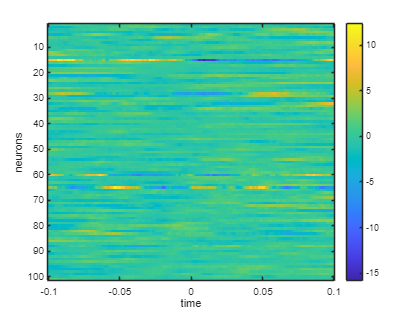


figure, imagesc(sta.time, 1:nNeurons, sta_all), colorbar
xlabel('time')
ylabel('neurons')

the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


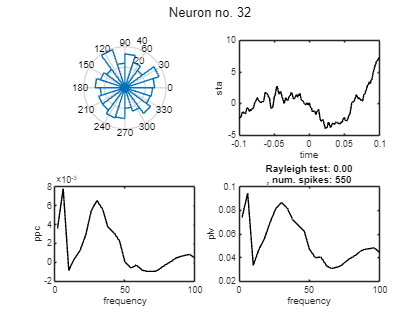

the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


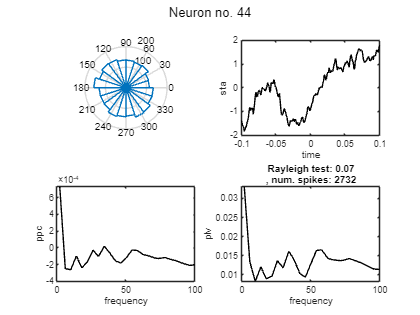

the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


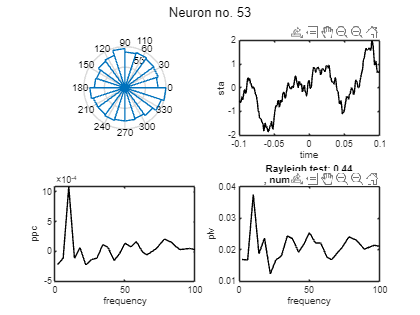

the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


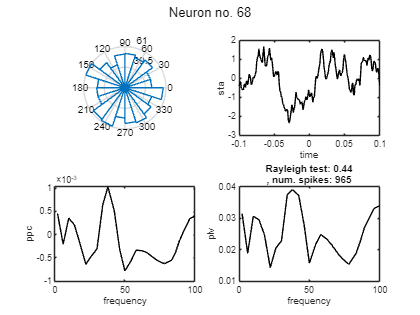

the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


the input is spike data with 109 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds


for iNeuron = [32, 44, 53, 68, 107]

    if length(sts.time{iNeuron})<3, continue,end

    f_ind = nearest(sts.freq, 10); 
    neuron_ind = iNeuron; 
    
    % compute the rayleigh test
    cfg = []; 
    cfg.spikechannel = neuron_ind; 
    cfg.method = 'ral';      
    stat_ral = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
    
    % for illustration also show the plv
    cfg = []; 
    cfg.spikechannel = neuron_ind; 
    cfg.method = 'plv';      
    stat_plv = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
           
    %
    figure, 
    subplot(2,2,1)
    % visualize the angles for this neuron
    angles = angle(sts.fourierspctrm{iNeuron}(:,:,f_ind));        
    rose(angles(:, 1),20)        
    
    % visualize the sta
    subplot(2,2,2)
    plot(sta.time, sta_all(iNeuron,:),'k')
    xlabel('time')
    ylabel('sta')

    % visualize the ppc for this neuron
    subplot(2,2,3)
    plot(stat_ppc.freq, ppc_all(iNeuron,:),'k')
    xlabel('frequency')
    ylabel('ppc')
    
    subplot(2,2,4)
    plot(stat_plv.freq, mean(stat_plv.plv, 1),'k')
    xlabel('frequency')
    ylabel('plv')

    title(sprintf("Rayleigh test: %2.2f\n, num. spikes: %d", stat_ral.ral(f_ind),n_spikes(iNeuron,f_ind)))
    sgtitle("Neuron no. " + num2str(iNeuron));
end

## PART 6: COMPUTE GROUP STATISTICS FOR ALL THE NEURONS

## weighted average 

[w_ppc,uw_ppc,thresh_ppc] = compute_avg_ppc(n_spikes,ppc_all);

% plot the results 
figure, 
h(1)=plot(stat_ppc.freq, w_ppc,'g'); 
hold on, 
h(2)=plot(stat_ppc.freq, uw_ppc,'r'); 
hold on, 
h(3)=plot(stat_ppc.freq, thresh_ppc,'b');
legend(h,'weighted', 'unweighted', 'threshold50')

## PART 7: COMPUTE THE SPECTRUM IN A DIFFERENT WAY, TAKING THE FOURIER AROUND EACH SPIKE

cfg = []; 
cfg.timwin= [-0.1 0.1]; 
cfg.foilim = [10 100]; 
cfg.taper = 'hann'; 
cfg.spikechannel = 1:length(spike.trial); 
sts_fft = ft_spiketriggeredspectrum_fft(cfg, lfp, spike); 

% 
nNeurons = length(spike.label); 
ppc_all = NaN(nNeurons, length(sts_fft.freq)); 
n_spikes = NaN(nNeurons, length(sts_fft.freq)); 
for iNeuron = 1:nNeurons

    if length(sts.time{iNeuron})<3, continue,end 
    
    % the code to compute for a single neuron
    cfg = []; 
    cfg.spikechannel = iNeuron; 
    cfg.method = 'ppc1'; 
    stat_ppc = ft_spiketriggeredspectrum_stat(cfg, sts_fft); % this function takes only one input at a time
    
    % collect the data in some array for all neurons
    ppc_all(iNeuron,:) = stat_ppc.ppc1; % collect the ppc values across units
    n_spikes(iNeuron,:) = stat_ppc.nspikes; % collect the number of spikes for each neuron
end

%
[w_ppc,uw_ppc,thresh_ppc] = compute_avg_ppc(n_spikes,ppc_all);

% plot the results 
figure, 
h(1)=plot(stat_ppc.freq, w_ppc,'g'); 
hold on, 
h(2)=plot(stat_ppc.freq, uw_ppc,'r'); 
hold on, 
h(3)=plot(stat_ppc.freq, thresh_ppc,'b');
legend(h,'weighted', 'unweighted', 'threshold50')

## PART 8: COMPUTE THE SPIKE FIELD COHERENCE

cfg = []; 
cfg.method = 'mtmfft'; 
cfg.taper = 'dpss';
cfg.foilim = [1 100];
cfg.tapsmofrq = 8;
cfg.output = 'fourier';
ft = ft_freqanalysis(cfg, data_all);

cfg = []; 
cfg.method = 'coh';
con = ft_connectivityanalysis(cfg, ft); 

coh_spike_lfp = squeeze(con.cohspctrm(1,:,:));
figure, plot(con.freq, nanmean(coh_spike_lfp,1)); 


## 
$$END$$
